# Cleanup LFP Data 204 and 206

## Load Datasets 

% Load each unhabituated trial for each
controls = {CT1, CT2, CT3, CT4, CT5, CT6, CT7, CT8}

controls = 1×8 cell array
    {1893260×2 single}    {3726858×2 single}    {3716176×2 single}    {3675772×2 single}    {3640352×2 single}    {3615364×2 single}    {3715866×2 single}    {3653016×2 single}


knockouts = {KO1, KO2, KO3, KO4, KO5, KO6, KO7, KO8}    

knockouts = 1×8 cell array
    {1890190×2 single}    {3689071×2 single}    {3517539×2 single}    {3770358×2 single}    {3691845×2 single}    {3938323×2 single}    {3639901×2 single}    {3861380×2 single}


## Set Chronux Parameters

% Setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 100]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 3; % the time-bandwidth product 
K = 5; % the number of tapers, K = 2*TW - 1 
params.tapers = [TW K]

params = struct with fields:
        Fs: 1000
     fpass: [0 100]
       pad: 0
    tapers: [3 5]


## Set Window and MovingWin Size

window = 20

window = 20

movingwin = [20 0.5]

movingwin =    20.0000    0.5000


## Plot Controls

ii is
     1



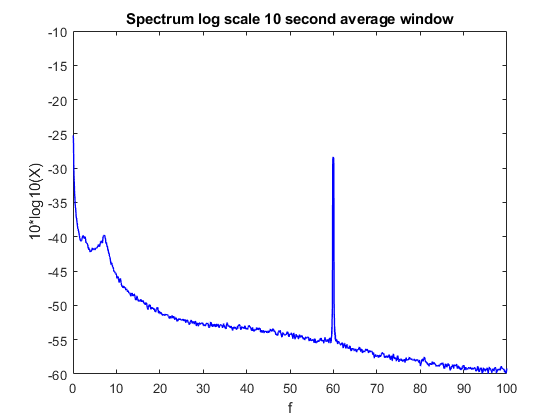

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


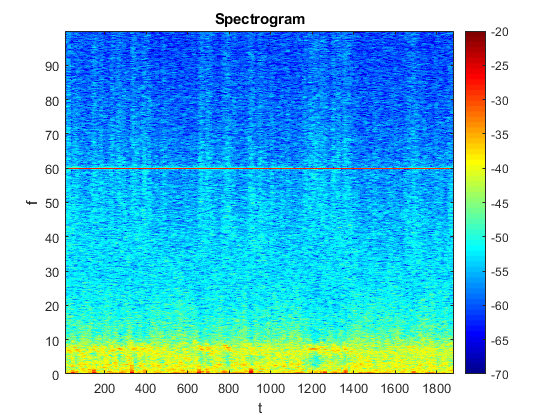

spectrogram done


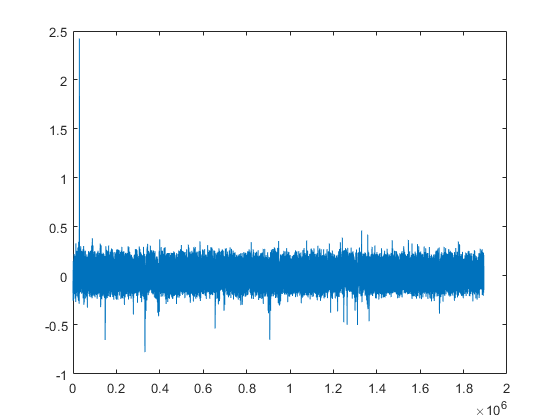

Raw Data trace done


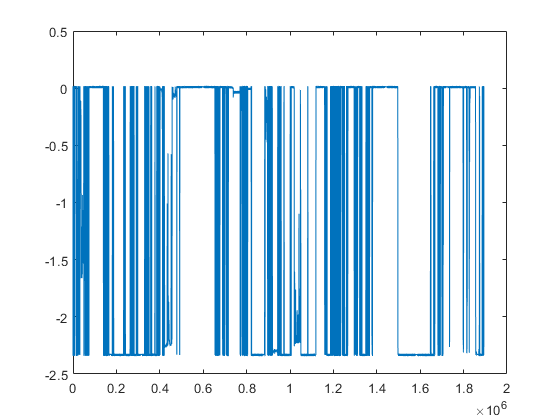

running trace done
ii is
     2



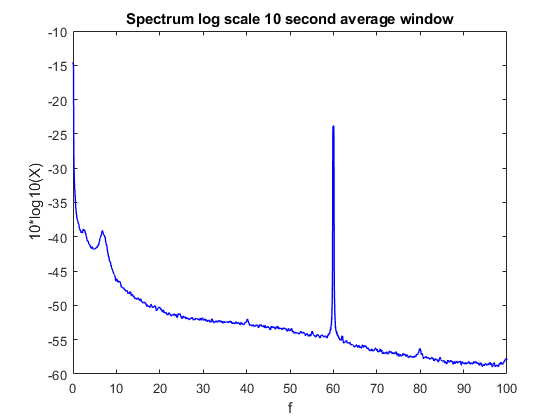

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


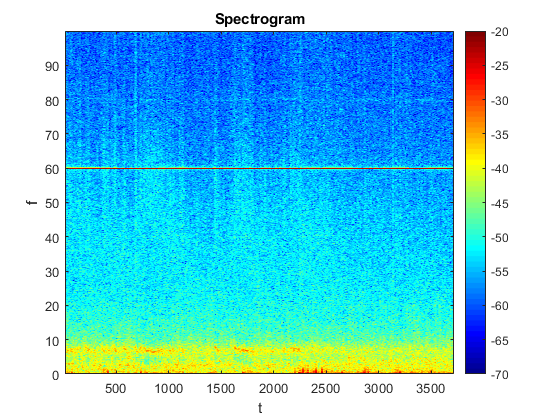

spectrogram done


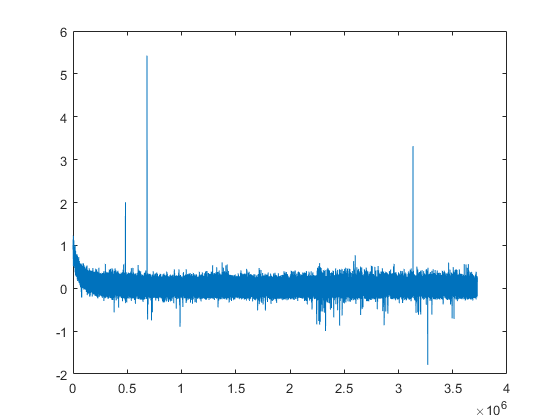

Raw Data trace done


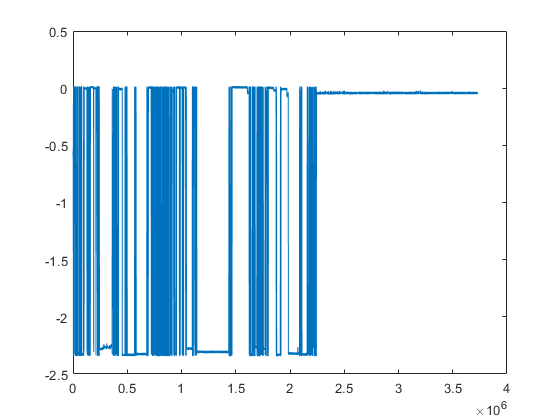

running trace done
ii is
     3



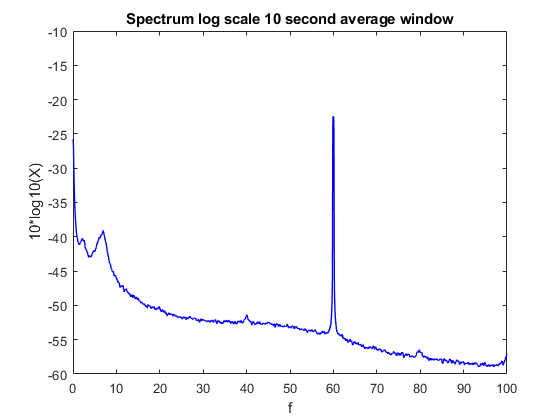

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


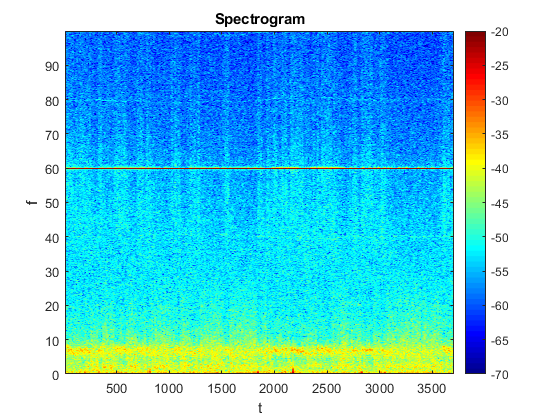

spectrogram done


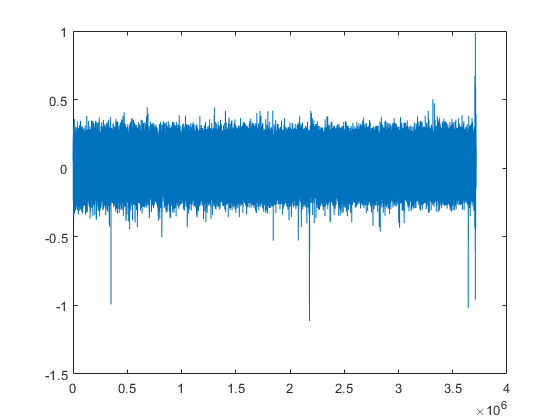

Raw Data trace done


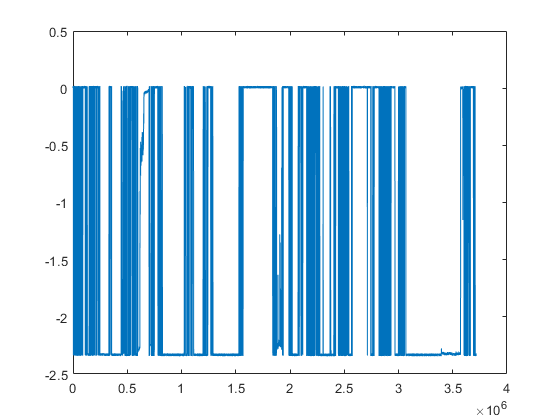

running trace done
ii is
     4



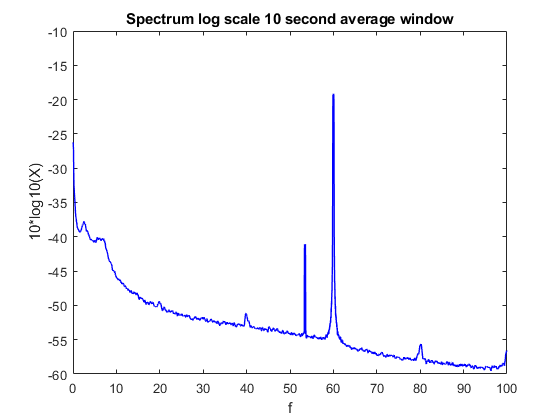

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


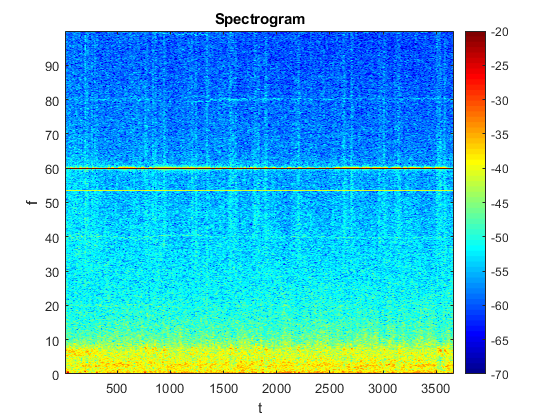

spectrogram done


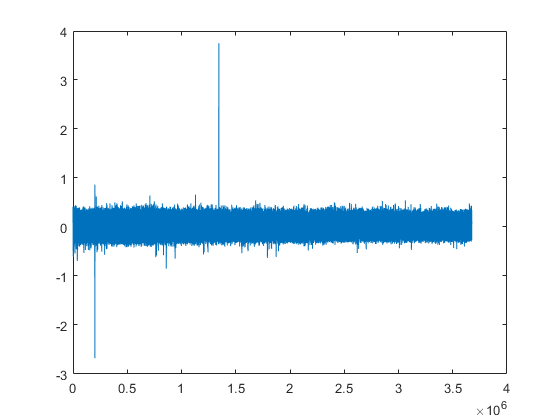

Raw Data trace done


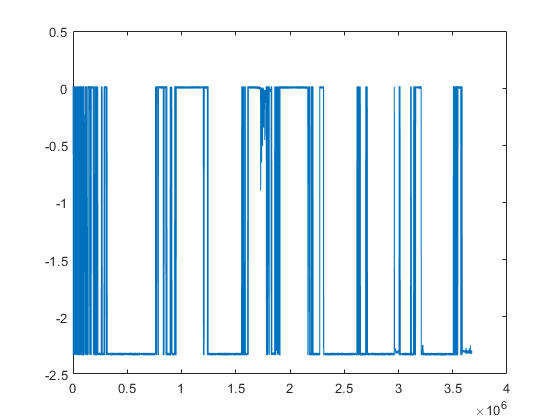

running trace done
ii is
     5



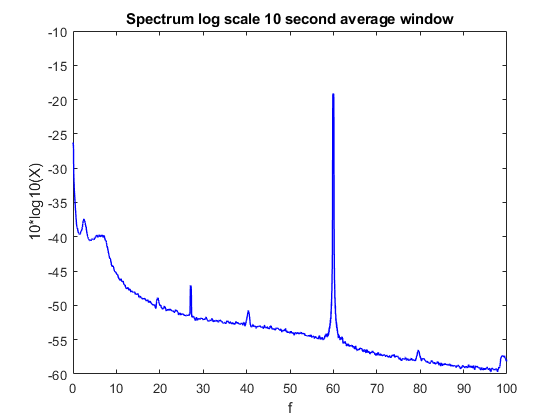

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


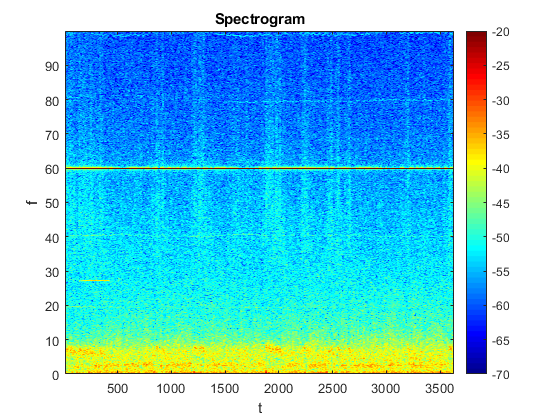

spectrogram done


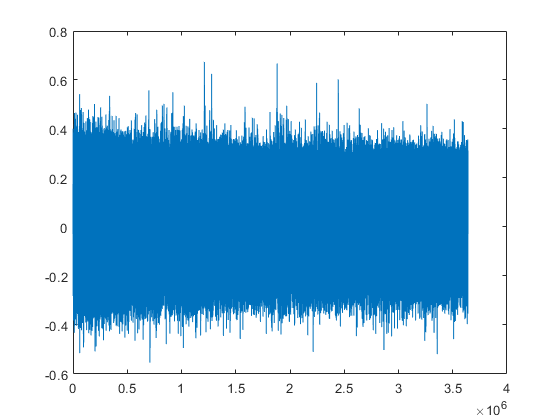

Raw Data trace done


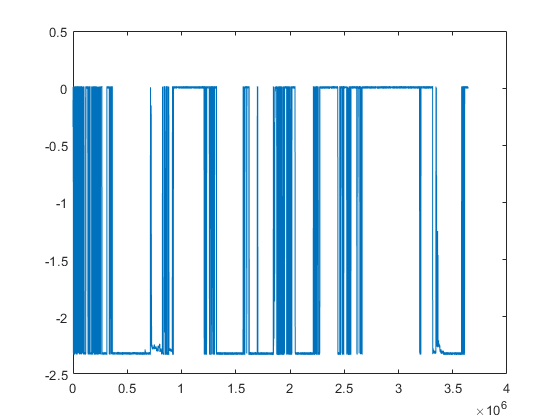

running trace done
ii is
     6



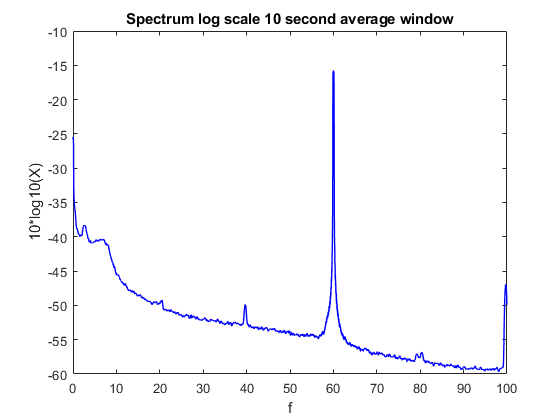

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


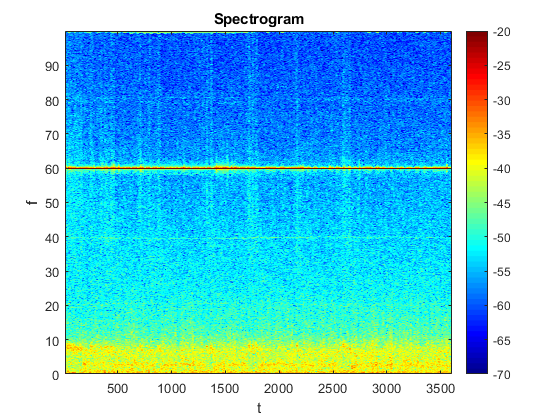

spectrogram done


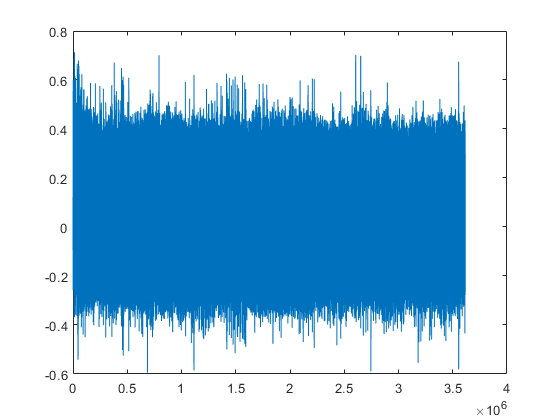

Raw Data trace done


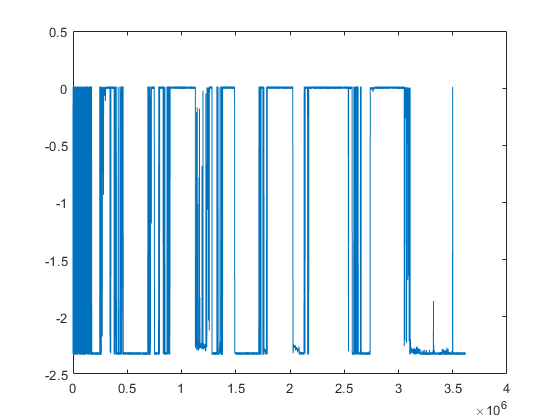

running trace done
ii is
     7



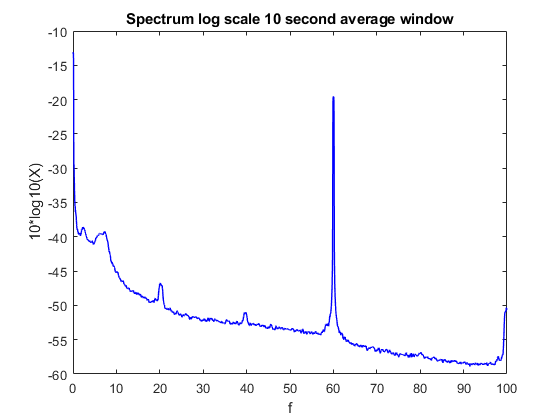

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


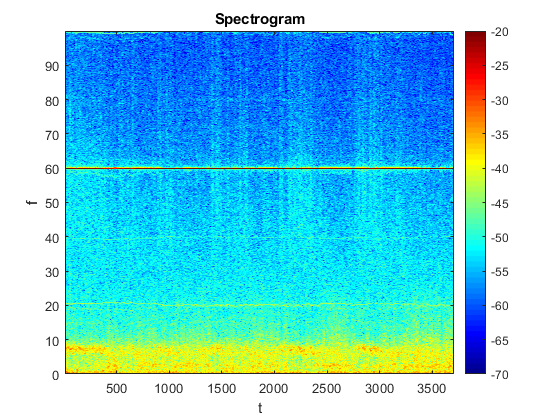

spectrogram done


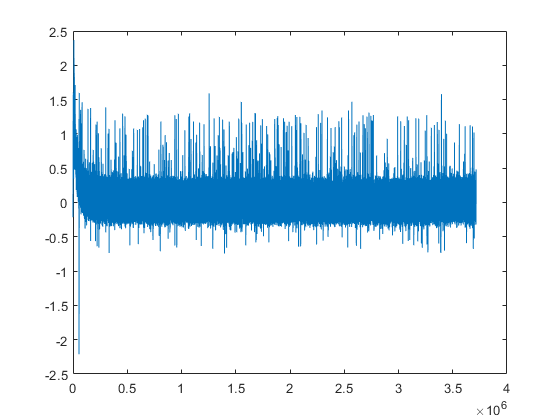

Raw Data trace done


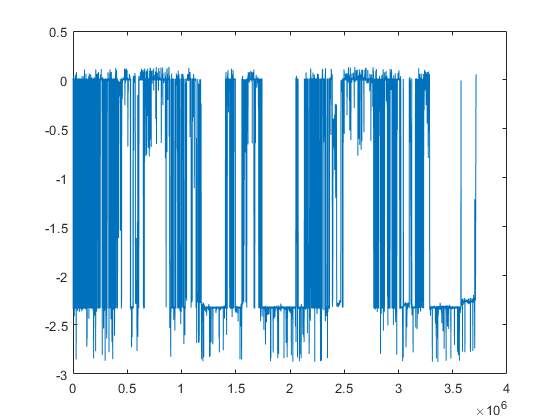

running trace done
ii is
     8



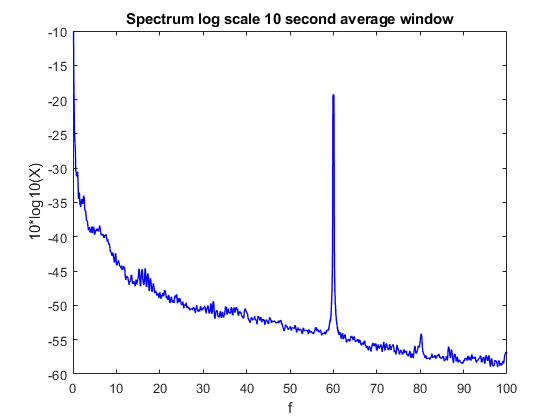

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


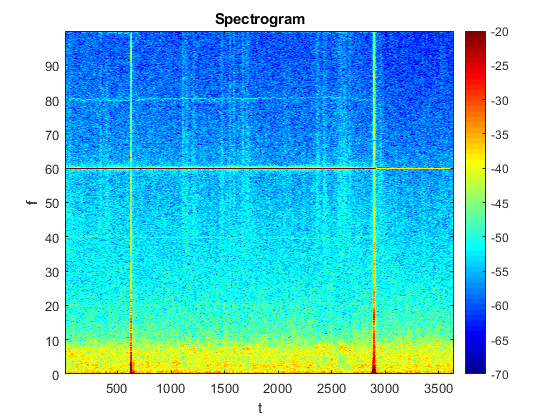

spectrogram done


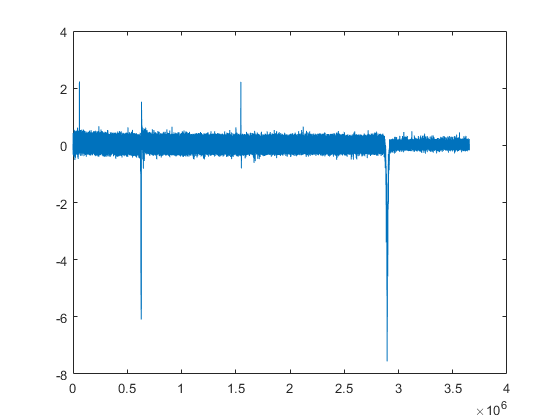

Raw Data trace done


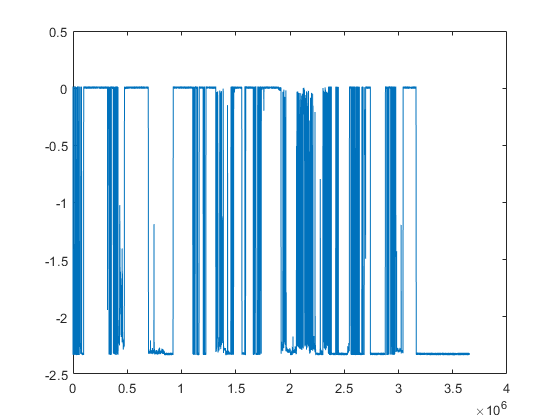

running trace done


plot_all(controls, params, window, movingwin)  

## Plot Knockouts

ii is
     1



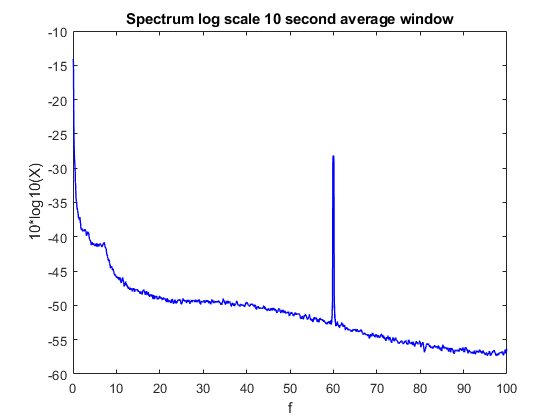

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


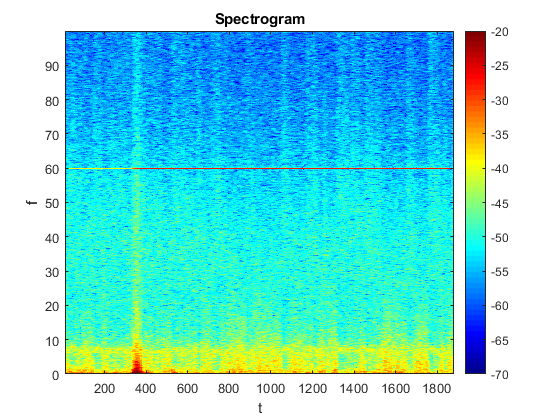

spectrogram done


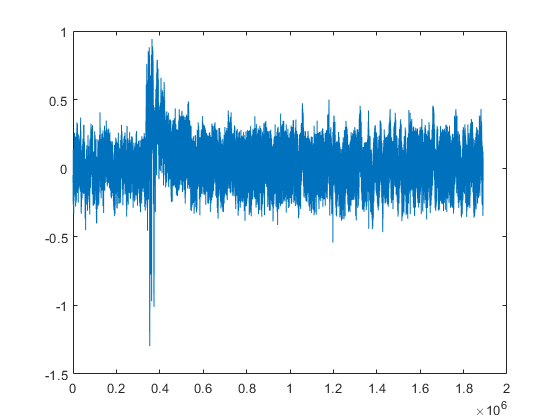

Raw Data trace done


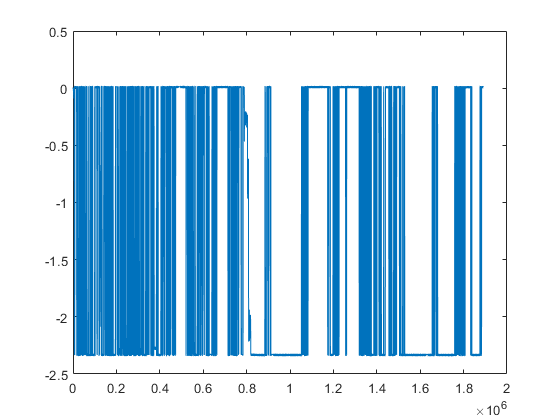

running trace done
ii is
     2



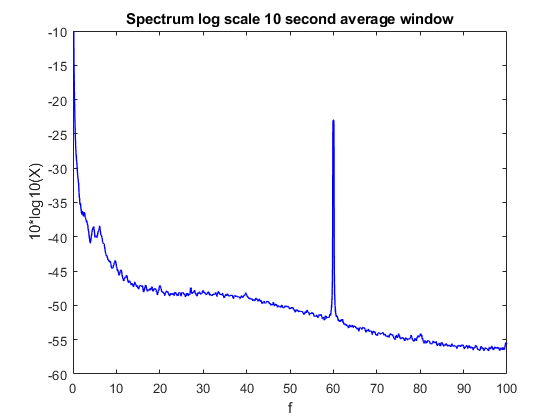

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


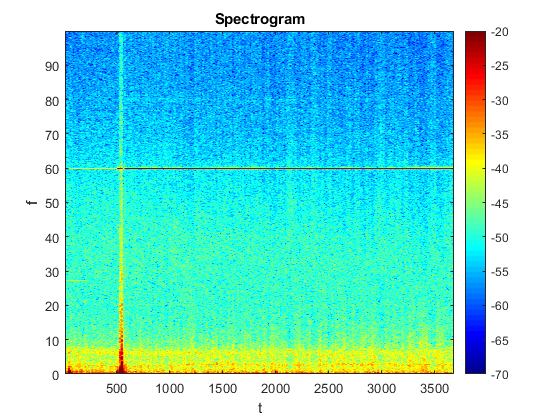

spectrogram done


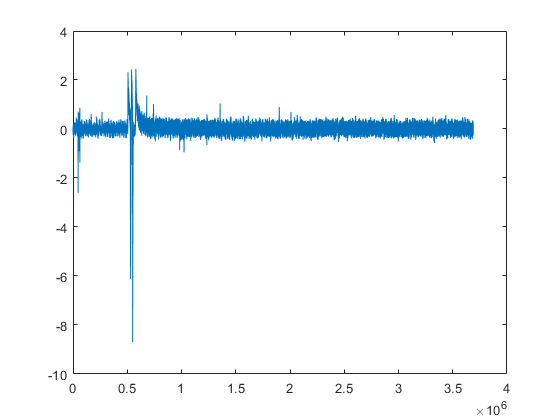

Raw Data trace done


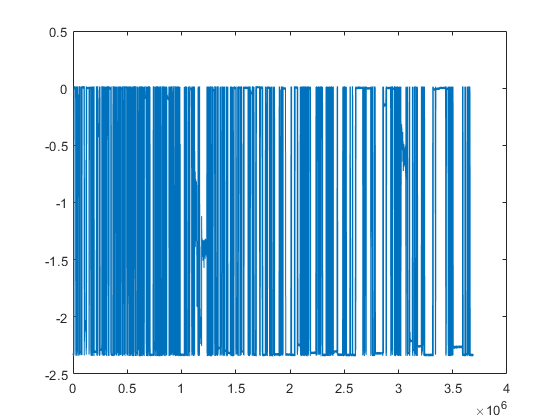

running trace done
ii is
     3



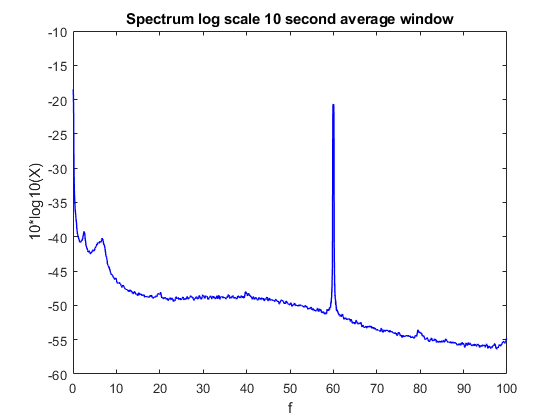

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


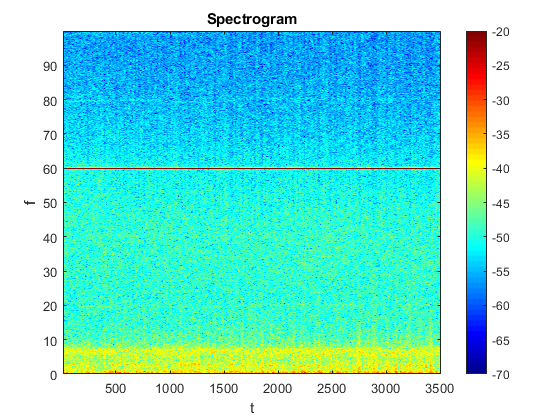

spectrogram done


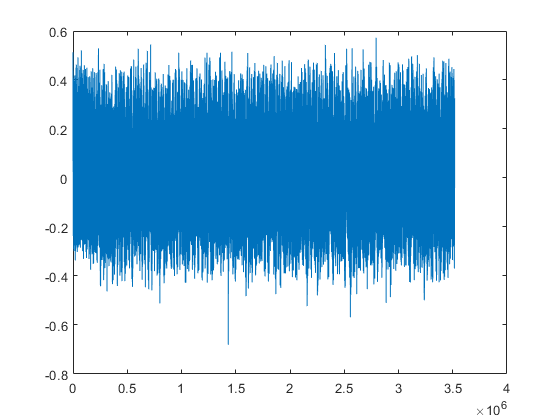

Raw Data trace done


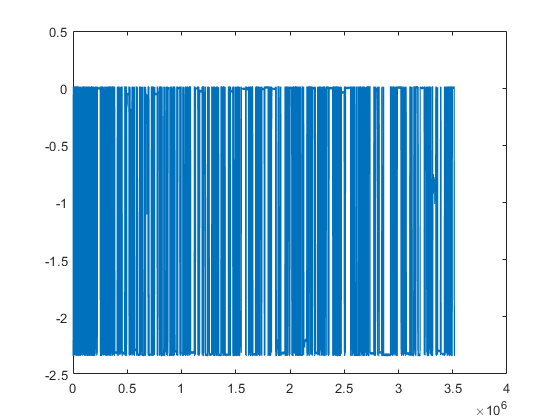

running trace done
ii is
     4



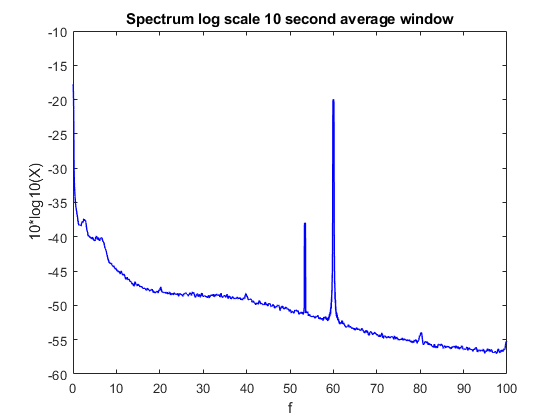

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


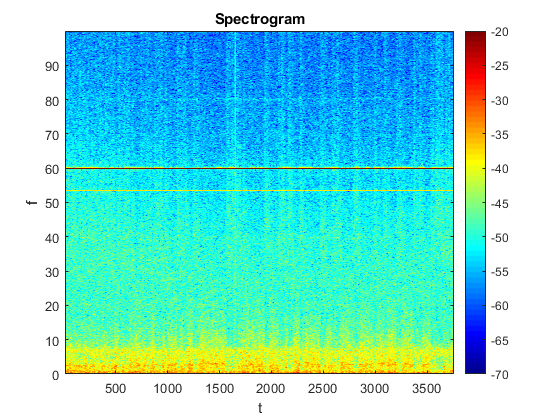

spectrogram done


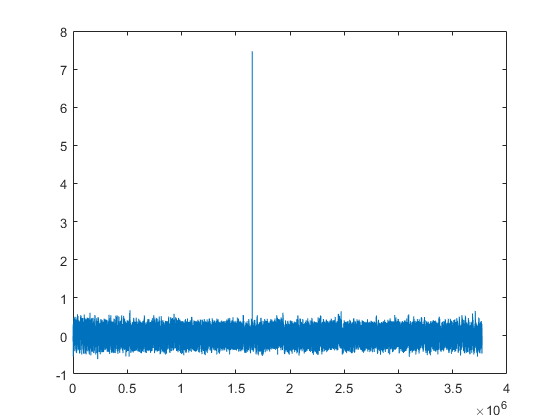

Raw Data trace done


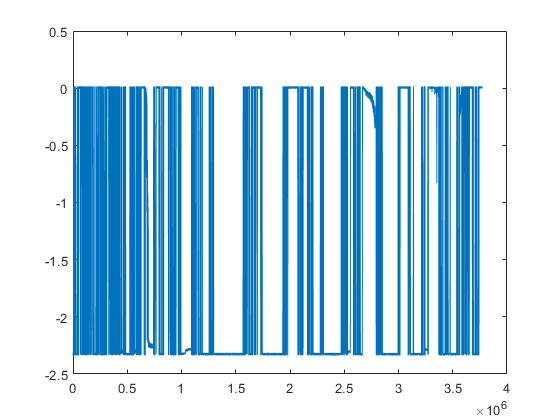

running trace done
ii is
     5



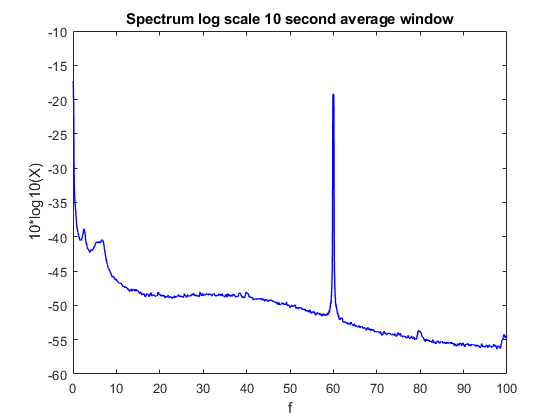

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


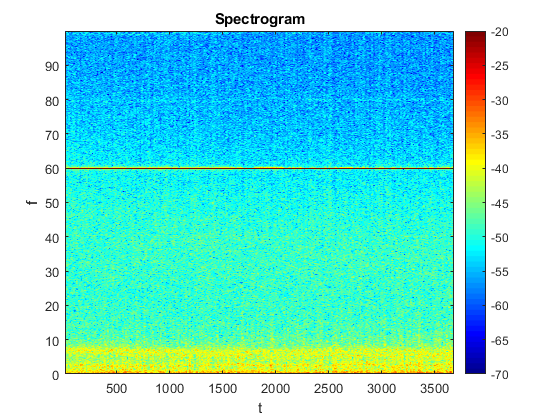

spectrogram done


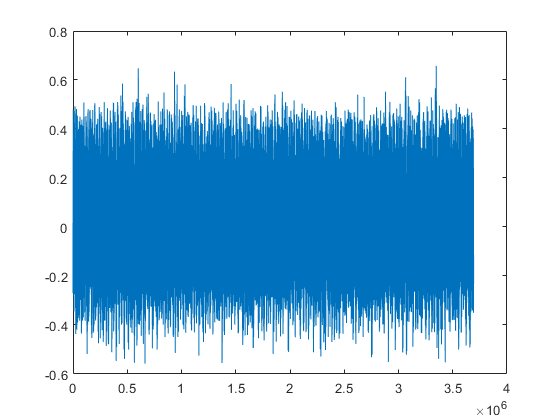

Raw Data trace done


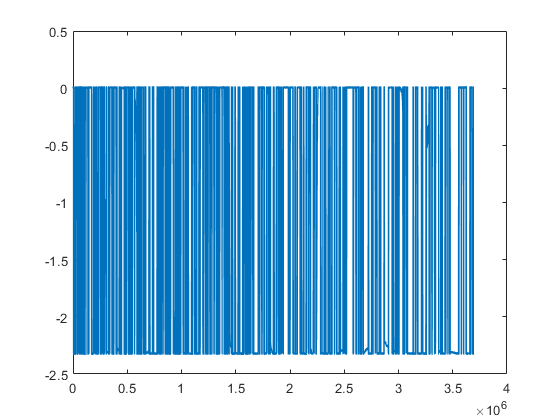

running trace done
ii is
     6



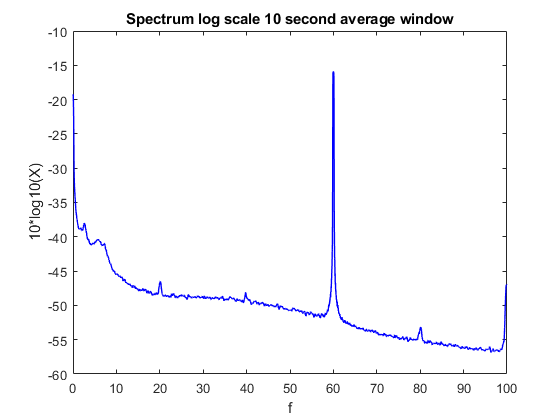

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


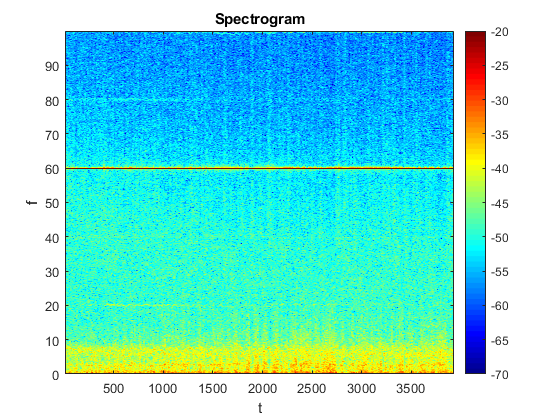

spectrogram done


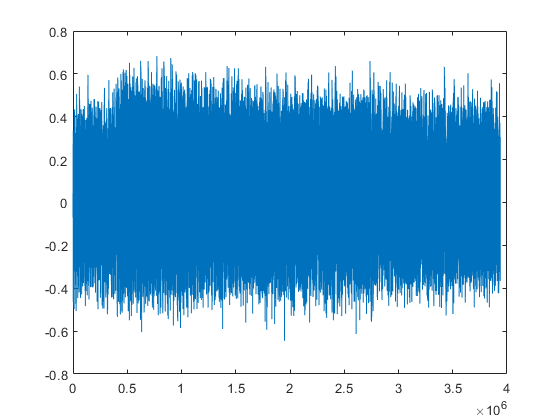

Raw Data trace done


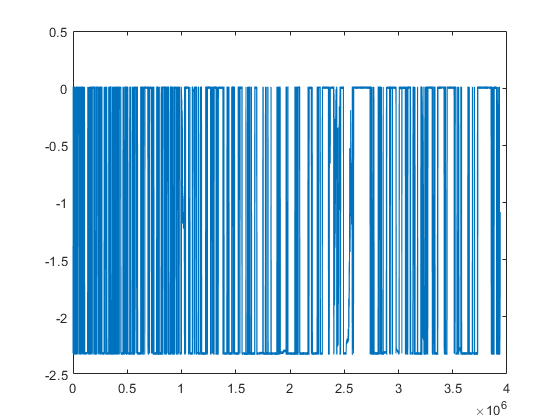

running trace done
ii is
     7



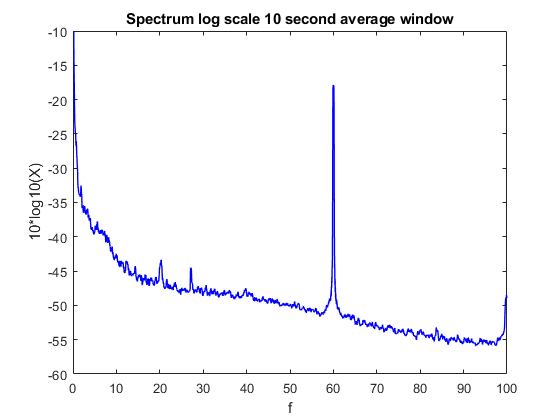

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


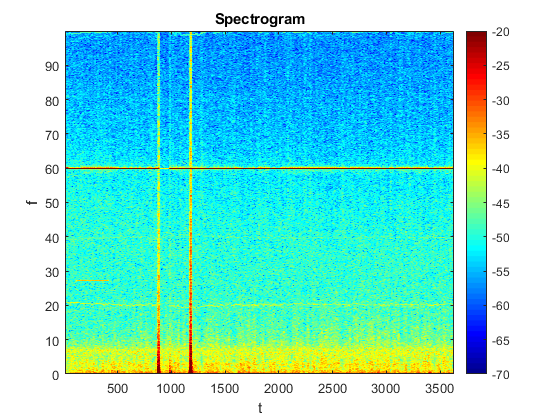

spectrogram done


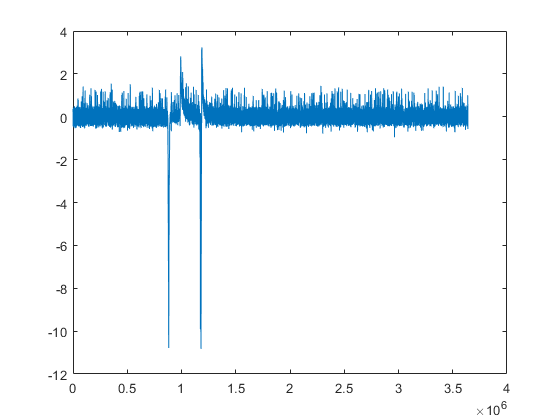

Raw Data trace done


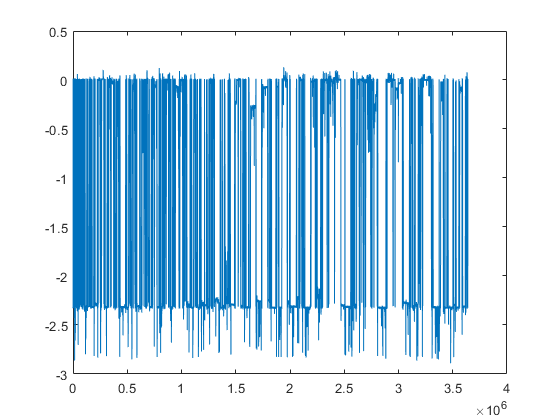

running trace done
ii is
     8



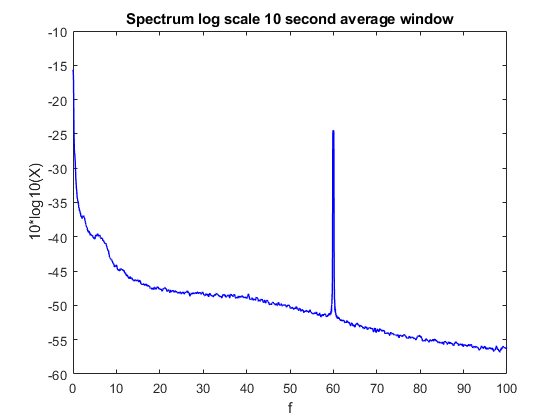

ans = 1×2 cell array
    {3277×1 single}    {1×3277 double}


spectrum done


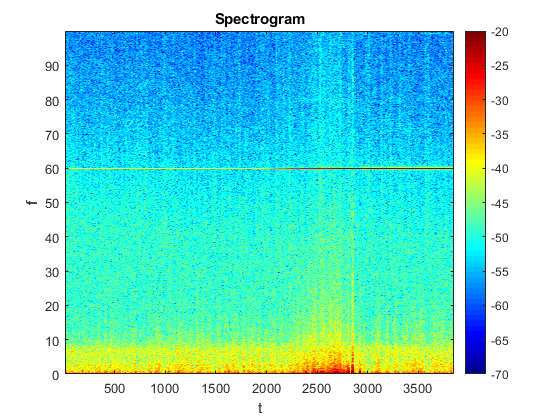

spectrogram done


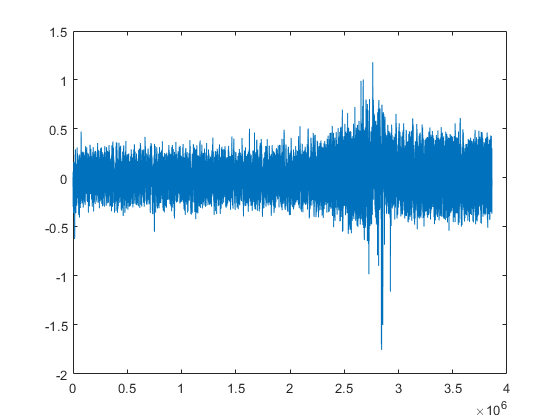

Raw Data trace done


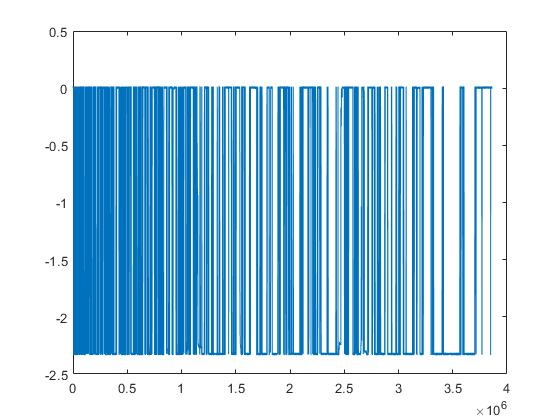

running trace done


plot_all(knockouts, params, window, movingwin)

## Test Artifact Filter

test = {KO1}

test = 1×1 cell array
    {1890190×2 single}



disp(test)

    [1890190×2 single]




xx = artifact_filter(test)

jj = 1

cell_array = 1×1 cell array
    {1890189×2 single}


cell_array = 1×1 cell array
    {1890188×2 single}


cell_array = 1×1 cell array
    {1890187×2 single}


cell_array = 1×1 cell array
    {1890186×2 single}


cell_array = 1×1 cell array
    {1890185×2 single}


cell_array = 1×1 cell array
    {1890184×2 single}


cell_array = 1×1 cell array
    {1890183×2 single}


cell_array = 1×1 cell array
    {1890182×2 single}


cell_array = 1×1 cell array
    {1890181×2 single}


cell_array = 1×1 cell array
    {1890180×2 single}


cell_array = 1×1 cell array
    {1890179×2 single}


cell_array = 1×1 cell array
    {1890178×2 single}


cell_array = 1×1 cell array
    {1890177×2 single}


cell_array = 1×1 cell array
    {1890176×2 single}


cell_array = 1×1 cell array
    {1890175×2 single}


cell_array = 1×1 cell array
    {1890174×2 single}


cell_array = 1×1 cell array
    {1890173×2 single}


cell_array = 1×1 cell array
    {1890172×2 single}


cell_array = 1×1 cell array
    {1890171×2 single}


cell_array = 1×1 cell array
    {1890170×2 single}


cell_array = 1×1 cell array
    {1890169×2 single}


cell_array = 1×1 cell array
    {1890168×2 single}


cell_array = 1×1 cell array
    {1890167×2 single}


cell_array = 1×1 cell array
    {1890166×2 single}


cell_array = 1×1 cell array
    {1890165×2 single}


cell_array = 1×1 cell array
    {1890164×2 single}


cell_array = 1×1 cell array
    {1890163×2 single}


cell_array = 1×1 cell array
    {1890162×2 single}


cell_array = 1×1 cell array
    {1890161×2 single}


cell_array = 1×1 cell array
    {1890160×2 single}


cell_array = 1×1 cell array
    {1890159×2 single}


cell_array = 1×1 cell array
    {1890158×2 single}


cell_array = 1×1 cell array
    {1890157×2 single}


cell_array = 1×1 cell array
    {1890156×2 single}


cell_array = 1×1 cell array
    {1890155×2 single}


cell_array = 1×1 cell array
    {1890154×2 single}


cell_array = 1×1 cell array
    {1890153×2 single}


cell_array = 1×1 cell array
    {1890152×2 single}


cell_array = 1×1 cell array
    {1890151×2 single}


cell_array = 1×1 cell array
    {1890150×2 single}


cell_array = 1×1 cell array
    {1890149×2 single}


cell_array = 1×1 cell array
    {1890148×2 single}


cell_array = 1×1 cell array
    {1890147×2 single}


cell_array = 1×1 cell array
    {1890146×2 single}


cell_array = 1×1 cell array
    {1890145×2 single}


cell_array = 1×1 cell array
    {1890144×2 single}


cell_array = 1×1 cell array
    {1890143×2 single}


cell_array = 1×1 cell array
    {1890142×2 single}


cell_array = 1×1 cell array
    {1890141×2 single}


cell_array = 1×1 cell array
    {1890140×2 single}


cell_array = 1×1 cell array
    {1890139×2 single}


cell_array = 1×1 cell array
    {1890138×2 single}


cell_array = 1×1 cell array
    {1890137×2 single}


cell_array = 1×1 cell array
    {1890136×2 single}


cell_array = 1×1 cell array
    {1890135×2 single}


cell_array = 1×1 cell array
    {1890134×2 single}


cell_array = 1×1 cell array
    {1890133×2 single}


cell_array = 1×1 cell array
    {1890132×2 single}


cell_array = 1×1 cell array
    {1890131×2 single}


cell_array = 1×1 cell array
    {1890130×2 single}


cell_array = 1×1 cell array
    {1890129×2 single}


cell_array = 1×1 cell array
    {1890128×2 single}


cell_array = 1×1 cell array
    {1890127×2 single}


cell_array = 1×1 cell array
    {1890126×2 single}


cell_array = 1×1 cell array
    {1890125×2 single}


cell_array = 1×1 cell array
    {1890124×2 single}


cell_array = 1×1 cell array
    {1890123×2 single}


cell_array = 1×1 cell array
    {1890122×2 single}


cell_array = 1×1 cell array
    {1890121×2 single}


cell_array = 1×1 cell array
    {1890120×2 single}


cell_array = 1×1 cell array
    {1890119×2 single}


cell_array = 1×1 cell array
    {1890118×2 single}


cell_array = 1×1 cell array
    {1890117×2 single}


cell_array = 1×1 cell array
    {1890116×2 single}


cell_array = 1×1 cell array
    {1890115×2 single}


cell_array = 1×1 cell array
    {1890114×2 single}


cell_array = 1×1 cell array
    {1890113×2 single}


cell_array = 1×1 cell array
    {1890112×2 single}


cell_array = 1×1 cell array
    {1890111×2 single}


cell_array = 1×1 cell array
    {1890110×2 single}


cell_array = 1×1 cell array
    {1890109×2 single}


cell_array = 1×1 cell array
    {1890108×2 single}


cell_array = 1×1 cell array
    {1890107×2 single}


cell_array = 1×1 cell array
    {1890106×2 single}


cell_array = 1×1 cell array
    {1890105×2 single}


cell_array = 1×1 cell array
    {1890104×2 single}


cell_array = 1×1 cell array
    {1890103×2 single}


cell_array = 1×1 cell array
    {1890102×2 single}


cell_array = 1×1 cell array
    {1890101×2 single}


cell_array = 1×1 cell array
    {1890100×2 single}


cell_array = 1×1 cell array
    {1890099×2 single}


cell_array = 1×1 cell array
    {1890098×2 single}


cell_array = 1×1 cell array
    {1890097×2 single}


cell_array = 1×1 cell array
    {1890096×2 single}


cell_array = 1×1 cell array
    {1890095×2 single}


cell_array = 1×1 cell array
    {1890094×2 single}


cell_array = 1×1 cell array
    {1890093×2 single}


cell_array = 1×1 cell array
    {1890092×2 single}


cell_array = 1×1 cell array
    {1890091×2 single}


cell_array = 1×1 cell array
    {1890090×2 single}


cell_array = 1×1 cell array
    {1890089×2 single}


cell_array = 1×1 cell array
    {1890088×2 single}


cell_array = 1×1 cell array
    {1890087×2 single}


cell_array = 1×1 cell array
    {1890086×2 single}


cell_array = 1×1 cell array
    {1890085×2 single}


cell_array = 1×1 cell array
    {1890084×2 single}


cell_array = 1×1 cell array
    {1890083×2 single}


cell_array = 1×1 cell array
    {1890082×2 single}


cell_array = 1×1 cell array
    {1890081×2 single}


cell_array = 1×1 cell array
    {1890080×2 single}


cell_array = 1×1 cell array
    {1890079×2 single}


cell_array = 1×1 cell array
    {1890078×2 single}


cell_array = 1×1 cell array
    {1890077×2 single}


cell_array = 1×1 cell array
    {1890076×2 single}


cell_array = 1×1 cell array
    {1890075×2 single}


cell_array = 1×1 cell array
    {1890074×2 single}


cell_array = 1×1 cell array
    {1890073×2 single}


cell_array = 1×1 cell array
    {1890072×2 single}


cell_array = 1×1 cell array
    {1890071×2 single}


cell_array = 1×1 cell array
    {1890070×2 single}


cell_array = 1×1 cell array
    {1890069×2 single}


cell_array = 1×1 cell array
    {1890068×2 single}


cell_array = 1×1 cell array
    {1890067×2 single}


cell_array = 1×1 cell array
    {1890066×2 single}


cell_array = 1×1 cell array
    {1890065×2 single}


cell_array = 1×1 cell array
    {1890064×2 single}


cell_array = 1×1 cell array
    {1890063×2 single}


cell_array = 1×1 cell array
    {1890062×2 single}


cell_array = 1×1 cell array
    {1890061×2 single}


cell_array = 1×1 cell array
    {1890060×2 single}


cell_array = 1×1 cell array
    {1890059×2 single}


cell_array = 1×1 cell array
    {1890058×2 single}


cell_array = 1×1 cell array
    {1890057×2 single}


cell_array = 1×1 cell array
    {1890056×2 single}


cell_array = 1×1 cell array
    {1890055×2 single}


cell_array = 1×1 cell array
    {1890054×2 single}


cell_array = 1×1 cell array
    {1890053×2 single}


cell_array = 1×1 cell array
    {1890052×2 single}


cell_array = 1×1 cell array
    {1890051×2 single}


cell_array = 1×1 cell array
    {1890050×2 single}


cell_array = 1×1 cell array
    {1890049×2 single}


cell_array = 1×1 cell array
    {1890048×2 single}


cell_array = 1×1 cell array
    {1890047×2 single}


cell_array = 1×1 cell array
    {1890046×2 single}


cell_array = 1×1 cell array
    {1890045×2 single}


cell_array = 1×1 cell array
    {1890044×2 single}


cell_array = 1×1 cell array
    {1890043×2 single}


cell_array = 1×1 cell array
    {1890042×2 single}


cell_array = 1×1 cell array
    {1890041×2 single}


cell_array = 1×1 cell array
    {1890040×2 single}


cell_array = 1×1 cell array
    {1890039×2 single}


cell_array = 1×1 cell array
    {1890038×2 single}


cell_array = 1×1 cell array
    {1890037×2 single}


cell_array = 1×1 cell array
    {1890036×2 single}


cell_array = 1×1 cell array
    {1890035×2 single}


cell_array = 1×1 cell array
    {1890034×2 single}


cell_array = 1×1 cell array
    {1890033×2 single}


cell_array = 1×1 cell array
    {1890032×2 single}


cell_array = 1×1 cell array
    {1890031×2 single}


cell_array = 1×1 cell array
    {1890030×2 single}


cell_array = 1×1 cell array
    {1890029×2 single}


cell_array = 1×1 cell array
    {1890028×2 single}


cell_array = 1×1 cell array
    {1890027×2 single}


cell_array = 1×1 cell array
    {1890026×2 single}


cell_array = 1×1 cell array
    {1890025×2 single}


cell_array = 1×1 cell array
    {1890024×2 single}


cell_array = 1×1 cell array
    {1890023×2 single}


cell_array = 1×1 cell array
    {1890022×2 single}


cell_array = 1×1 cell array
    {1890021×2 single}


cell_array = 1×1 cell array
    {1890020×2 single}


cell_array = 1×1 cell array
    {1890019×2 single}


cell_array = 1×1 cell array
    {1890018×2 single}


cell_array = 1×1 cell array
    {1890017×2 single}


cell_array = 1×1 cell array
    {1890016×2 single}


cell_array = 1×1 cell array
    {1890015×2 single}


cell_array = 1×1 cell array
    {1890014×2 single}


cell_array = 1×1 cell array
    {1890013×2 single}


cell_array = 1×1 cell array
    {1890012×2 single}


cell_array = 1×1 cell array
    {1890011×2 single}


cell_array = 1×1 cell array
    {1890010×2 single}


cell_array = 1×1 cell array
    {1890009×2 single}


cell_array = 1×1 cell array
    {1890008×2 single}


cell_array = 1×1 cell array
    {1890007×2 single}


cell_array = 1×1 cell array
    {1890006×2 single}


cell_array = 1×1 cell array
    {1890005×2 single}


cell_array = 1×1 cell array
    {1890004×2 single}


cell_array = 1×1 cell array
    {1890003×2 single}


cell_array = 1×1 cell array
    {1890002×2 single}


cell_array = 1×1 cell array
    {1890001×2 single}


cell_array = 1×1 cell array
    {1890000×2 single}


cell_array = 1×1 cell array
    {1889999×2 single}


cell_array = 1×1 cell array
    {1889998×2 single}


cell_array = 1×1 cell array
    {1889997×2 single}


cell_array = 1×1 cell array
    {1889996×2 single}


cell_array = 1×1 cell array
    {1889995×2 single}


cell_array = 1×1 cell array
    {1889994×2 single}


cell_array = 1×1 cell array
    {1889993×2 single}


cell_array = 1×1 cell array
    {1889992×2 single}


cell_array = 1×1 cell array
    {1889991×2 single}


cell_array = 1×1 cell array
    {1889990×2 single}


cell_array = 1×1 cell array
    {1889989×2 single}


cell_array = 1×1 cell array
    {1889988×2 single}


cell_array = 1×1 cell array
    {1889987×2 single}


cell_array = 1×1 cell array
    {1889986×2 single}


cell_array = 1×1 cell array
    {1889985×2 single}


cell_array = 1×1 cell array
    {1889984×2 single}


cell_array = 1×1 cell array
    {1889983×2 single}


cell_array = 1×1 cell array
    {1889982×2 single}


cell_array = 1×1 cell array
    {1889981×2 single}


cell_array = 1×1 cell array
    {1889980×2 single}


cell_array = 1×1 cell array
    {1889979×2 single}


cell_array = 1×1 cell array
    {1889978×2 single}


cell_array = 1×1 cell array
    {1889977×2 single}


cell_array = 1×1 cell array
    {1889976×2 single}


cell_array = 1×1 cell array
    {1889975×2 single}


cell_array = 1×1 cell array
    {1889974×2 single}


cell_array = 1×1 cell array
    {1889973×2 single}


cell_array = 1×1 cell array
    {1889972×2 single}


cell_array = 1×1 cell array
    {1889971×2 single}


cell_array = 1×1 cell array
    {1889970×2 single}


cell_array = 1×1 cell array
    {1889969×2 single}


cell_array = 1×1 cell array
    {1889968×2 single}


cell_array = 1×1 cell array
    {1889967×2 single}


cell_array = 1×1 cell array
    {1889966×2 single}


cell_array = 1×1 cell array
    {1889965×2 single}


cell_array = 1×1 cell array
    {1889964×2 single}


cell_array = 1×1 cell array
    {1889963×2 single}


cell_array = 1×1 cell array
    {1889962×2 single}


cell_array = 1×1 cell array
    {1889961×2 single}


cell_array = 1×1 cell array
    {1889960×2 single}


cell_array = 1×1 cell array
    {1889959×2 single}


cell_array = 1×1 cell array
    {1889958×2 single}


cell_array = 1×1 cell array
    {1889957×2 single}


cell_array = 1×1 cell array
    {1889956×2 single}


cell_array = 1×1 cell array
    {1889955×2 single}


cell_array = 1×1 cell array
    {1889954×2 single}


cell_array = 1×1 cell array
    {1889953×2 single}


cell_array = 1×1 cell array
    {1889952×2 single}


cell_array = 1×1 cell array
    {1889951×2 single}


cell_array = 1×1 cell array
    {1889950×2 single}


cell_array = 1×1 cell array
    {1889949×2 single}


cell_array = 1×1 cell array
    {1889948×2 single}


cell_array = 1×1 cell array
    {1889947×2 single}


cell_array = 1×1 cell array
    {1889946×2 single}


cell_array = 1×1 cell array
    {1889945×2 single}


cell_array = 1×1 cell array
    {1889944×2 single}


cell_array = 1×1 cell array
    {1889943×2 single}


cell_array = 1×1 cell array
    {1889942×2 single}


cell_array = 1×1 cell array
    {1889941×2 single}


cell_array = 1×1 cell array
    {1889940×2 single}


cell_array = 1×1 cell array
    {1889939×2 single}


cell_array = 1×1 cell array
    {1889938×2 single}


cell_array = 1×1 cell array
    {1889937×2 single}


cell_array = 1×1 cell array
    {1889936×2 single}


cell_array = 1×1 cell array
    {1889935×2 single}


cell_array = 1×1 cell array
    {1889934×2 single}


cell_array = 1×1 cell array
    {1889933×2 single}


cell_array = 1×1 cell array
    {1889932×2 single}


cell_array = 1×1 cell array
    {1889931×2 single}


cell_array = 1×1 cell array
    {1889930×2 single}


cell_array = 1×1 cell array
    {1889929×2 single}


cell_array = 1×1 cell array
    {1889928×2 single}


cell_array = 1×1 cell array
    {1889927×2 single}


cell_array = 1×1 cell array
    {1889926×2 single}


cell_array = 1×1 cell array
    {1889925×2 single}


cell_array = 1×1 cell array
    {1889924×2 single}


cell_array = 1×1 cell array
    {1889923×2 single}


cell_array = 1×1 cell array
    {1889922×2 single}


cell_array = 1×1 cell array
    {1889921×2 single}


cell_array = 1×1 cell array
    {1889920×2 single}


cell_array = 1×1 cell array
    {1889919×2 single}


cell_array = 1×1 cell array
    {1889918×2 single}


cell_array = 1×1 cell array
    {1889917×2 single}


cell_array = 1×1 cell array
    {1889916×2 single}


cell_array = 1×1 cell array
    {1889915×2 single}


cell_array = 1×1 cell array
    {1889914×2 single}


cell_array = 1×1 cell array
    {1889913×2 single}


cell_array = 1×1 cell array
    {1889912×2 single}


cell_array = 1×1 cell array
    {1889911×2 single}


cell_array = 1×1 cell array
    {1889910×2 single}


cell_array = 1×1 cell array
    {1889909×2 single}


cell_array = 1×1 cell array
    {1889908×2 single}


cell_array = 1×1 cell array
    {1889907×2 single}


cell_array = 1×1 cell array
    {1889906×2 single}


cell_array = 1×1 cell array
    {1889905×2 single}


cell_array = 1×1 cell array
    {1889904×2 single}


cell_array = 1×1 cell array
    {1889903×2 single}


cell_array = 1×1 cell array
    {1889902×2 single}


cell_array = 1×1 cell array
    {1889901×2 single}


cell_array = 1×1 cell array
    {1889900×2 single}


cell_array = 1×1 cell array
    {1889899×2 single}


cell_array = 1×1 cell array
    {1889898×2 single}


cell_array = 1×1 cell array
    {1889897×2 single}


cell_array = 1×1 cell array
    {1889896×2 single}


cell_array = 1×1 cell array
    {1889895×2 single}


cell_array = 1×1 cell array
    {1889894×2 single}


cell_array = 1×1 cell array
    {1889893×2 single}


cell_array = 1×1 cell array
    {1889892×2 single}


cell_array = 1×1 cell array
    {1889891×2 single}


cell_array = 1×1 cell array
    {1889890×2 single}


cell_array = 1×1 cell array
    {1889889×2 single}


cell_array = 1×1 cell array
    {1889888×2 single}


cell_array = 1×1 cell array
    {1889887×2 single}


cell_array = 1×1 cell array
    {1889886×2 single}


cell_array = 1×1 cell array
    {1889885×2 single}


cell_array = 1×1 cell array
    {1889884×2 single}


cell_array = 1×1 cell array
    {1889883×2 single}


cell_array = 1×1 cell array
    {1889882×2 single}


cell_array = 1×1 cell array
    {1889881×2 single}


cell_array = 1×1 cell array
    {1889880×2 single}


cell_array = 1×1 cell array
    {1889879×2 single}


cell_array = 1×1 cell array
    {1889878×2 single}


cell_array = 1×1 cell array
    {1889877×2 single}


cell_array = 1×1 cell array
    {1889876×2 single}


cell_array = 1×1 cell array
    {1889875×2 single}


cell_array = 1×1 cell array
    {1889874×2 single}


cell_array = 1×1 cell array
    {1889873×2 single}


cell_array = 1×1 cell array
    {1889872×2 single}


cell_array = 1×1 cell array
    {1889871×2 single}


cell_array = 1×1 cell array
    {1889870×2 single}


cell_array = 1×1 cell array
    {1889869×2 single}


cell_array = 1×1 cell array
    {1889868×2 single}


cell_array = 1×1 cell array
    {1889867×2 single}


cell_array = 1×1 cell array
    {1889866×2 single}


cell_array = 1×1 cell array
    {1889865×2 single}


cell_array = 1×1 cell array
    {1889864×2 single}


cell_array = 1×1 cell array
    {1889863×2 single}


cell_array = 1×1 cell array
    {1889862×2 single}


cell_array = 1×1 cell array
    {1889861×2 single}


cell_array = 1×1 cell array
    {1889860×2 single}


cell_array = 1×1 cell array
    {1889859×2 single}


cell_array = 1×1 cell array
    {1889858×2 single}


cell_array = 1×1 cell array
    {1889857×2 single}


cell_array = 1×1 cell array
    {1889856×2 single}


cell_array = 1×1 cell array
    {1889855×2 single}


cell_array = 1×1 cell array
    {1889854×2 single}


cell_array = 1×1 cell array
    {1889853×2 single}


cell_array = 1×1 cell array
    {1889852×2 single}


cell_array = 1×1 cell array
    {1889851×2 single}


cell_array = 1×1 cell array
    {1889850×2 single}


cell_array = 1×1 cell array
    {1889849×2 single}


cell_array = 1×1 cell array
    {1889848×2 single}


cell_array = 1×1 cell array
    {1889847×2 single}


cell_array = 1×1 cell array
    {1889846×2 single}


cell_array = 1×1 cell array
    {1889845×2 single}


cell_array = 1×1 cell array
    {1889844×2 single}


cell_array = 1×1 cell array
    {1889843×2 single}


cell_array = 1×1 cell array
    {1889842×2 single}


cell_array = 1×1 cell array
    {1889841×2 single}


cell_array = 1×1 cell array
    {1889840×2 single}


cell_array = 1×1 cell array
    {1889839×2 single}


cell_array = 1×1 cell array
    {1889838×2 single}


cell_array = 1×1 cell array
    {1889837×2 single}


cell_array = 1×1 cell array
    {1889836×2 single}


cell_array = 1×1 cell array
    {1889835×2 single}


cell_array = 1×1 cell array
    {1889834×2 single}


cell_array = 1×1 cell array
    {1889833×2 single}


cell_array = 1×1 cell array
    {1889832×2 single}


cell_array = 1×1 cell array
    {1889831×2 single}


cell_array = 1×1 cell array
    {1889830×2 single}


cell_array = 1×1 cell array
    {1889829×2 single}


cell_array = 1×1 cell array
    {1889828×2 single}


cell_array = 1×1 cell array
    {1889827×2 single}


cell_array = 1×1 cell array
    {1889826×2 single}


cell_array = 1×1 cell array
    {1889825×2 single}


cell_array = 1×1 cell array
    {1889824×2 single}


cell_array = 1×1 cell array
    {1889823×2 single}


cell_array = 1×1 cell array
    {1889822×2 single}


cell_array = 1×1 cell array
    {1889821×2 single}


cell_array = 1×1 cell array
    {1889820×2 single}


cell_array = 1×1 cell array
    {1889819×2 single}


cell_array = 1×1 cell array
    {1889818×2 single}


cell_array = 1×1 cell array
    {1889817×2 single}


cell_array = 1×1 cell array
    {1889816×2 single}


cell_array = 1×1 cell array
    {1889815×2 single}


cell_array = 1×1 cell array
    {1889814×2 single}


cell_array = 1×1 cell array
    {1889813×2 single}


cell_array = 1×1 cell array
    {1889812×2 single}


cell_array = 1×1 cell array
    {1889811×2 single}


cell_array = 1×1 cell array
    {1889810×2 single}


cell_array = 1×1 cell array
    {1889809×2 single}


cell_array = 1×1 cell array
    {1889808×2 single}


cell_array = 1×1 cell array
    {1889807×2 single}


cell_array = 1×1 cell array
    {1889806×2 single}


cell_array = 1×1 cell array
    {1889805×2 single}


cell_array = 1×1 cell array
    {1889804×2 single}


cell_array = 1×1 cell array
    {1889803×2 single}


cell_array = 1×1 cell array
    {1889802×2 single}


cell_array = 1×1 cell array
    {1889801×2 single}


cell_array = 1×1 cell array
    {1889800×2 single}


cell_array = 1×1 cell array
    {1889799×2 single}


cell_array = 1×1 cell array
    {1889798×2 single}


cell_array = 1×1 cell array
    {1889797×2 single}


cell_array = 1×1 cell array
    {1889796×2 single}


cell_array = 1×1 cell array
    {1889795×2 single}


cell_array = 1×1 cell array
    {1889794×2 single}


cell_array = 1×1 cell array
    {1889793×2 single}


cell_array = 1×1 cell array
    {1889792×2 single}


cell_array = 1×1 cell array
    {1889791×2 single}


cell_array = 1×1 cell array
    {1889790×2 single}


cell_array = 1×1 cell array
    {1889789×2 single}


cell_array = 1×1 cell array
    {1889788×2 single}


cell_array = 1×1 cell array
    {1889787×2 single}


cell_array = 1×1 cell array
    {1889786×2 single}


cell_array = 1×1 cell array
    {1889785×2 single}


cell_array = 1×1 cell array
    {1889784×2 single}


cell_array = 1×1 cell array
    {1889783×2 single}


cell_array = 1×1 cell array
    {1889782×2 single}


cell_array = 1×1 cell array
    {1889781×2 single}


cell_array = 1×1 cell array
    {1889780×2 single}


cell_array = 1×1 cell array
    {1889779×2 single}


cell_array = 1×1 cell array
    {1889778×2 single}


cell_array = 1×1 cell array
    {1889777×2 single}


cell_array = 1×1 cell array
    {1889776×2 single}


cell_array = 1×1 cell array
    {1889775×2 single}


cell_array = 1×1 cell array
    {1889774×2 single}


cell_array = 1×1 cell array
    {1889773×2 single}


cell_array = 1×1 cell array
    {1889772×2 single}


cell_array = 1×1 cell array
    {1889771×2 single}


cell_array = 1×1 cell array
    {1889770×2 single}


cell_array = 1×1 cell array
    {1889769×2 single}


cell_array = 1×1 cell array
    {1889768×2 single}


cell_array = 1×1 cell array
    {1889767×2 single}


cell_array = 1×1 cell array
    {1889766×2 single}


cell_array = 1×1 cell array
    {1889765×2 single}


cell_array = 1×1 cell array
    {1889764×2 single}


cell_array = 1×1 cell array
    {1889763×2 single}


cell_array = 1×1 cell array
    {1889762×2 single}


cell_array = 1×1 cell array
    {1889761×2 single}


cell_array = 1×1 cell array
    {1889760×2 single}


cell_array = 1×1 cell array
    {1889759×2 single}


cell_array = 1×1 cell array
    {1889758×2 single}


cell_array = 1×1 cell array
    {1889757×2 single}


cell_array = 1×1 cell array
    {1889756×2 single}


cell_array = 1×1 cell array
    {1889755×2 single}


cell_array = 1×1 cell array
    {1889754×2 single}


cell_array = 1×1 cell array
    {1889753×2 single}


cell_array = 1×1 cell array
    {1889752×2 single}


cell_array = 1×1 cell array
    {1889751×2 single}


cell_array = 1×1 cell array
    {1889750×2 single}


cell_array = 1×1 cell array
    {1889749×2 single}


cell_array = 1×1 cell array
    {1889748×2 single}


cell_array = 1×1 cell array
    {1889747×2 single}


cell_array = 1×1 cell array
    {1889746×2 single}


cell_array = 1×1 cell array
    {1889745×2 single}


cell_array = 1×1 cell array
    {1889744×2 single}


cell_array = 1×1 cell array
    {1889743×2 single}


cell_array = 1×1 cell array
    {1889742×2 single}


cell_array = 1×1 cell array
    {1889741×2 single}


cell_array = 1×1 cell array
    {1889740×2 single}


cell_array = 1×1 cell array
    {1889739×2 single}


cell_array = 1×1 cell array
    {1889738×2 single}


cell_array = 1×1 cell array
    {1889737×2 single}


cell_array = 1×1 cell array
    {1889736×2 single}


cell_array = 1×1 cell array
    {1889735×2 single}


cell_array = 1×1 cell array
    {1889734×2 single}


cell_array = 1×1 cell array
    {1889733×2 single}


cell_array = 1×1 cell array
    {1889732×2 single}


cell_array = 1×1 cell array
    {1889731×2 single}


cell_array = 1×1 cell array
    {1889730×2 single}


cell_array = 1×1 cell array
    {1889729×2 single}


cell_array = 1×1 cell array
    {1889728×2 single}


cell_array = 1×1 cell array
    {1889727×2 single}


cell_array = 1×1 cell array
    {1889726×2 single}


cell_array = 1×1 cell array
    {1889725×2 single}


cell_array = 1×1 cell array
    {1889724×2 single}


cell_array = 1×1 cell array
    {1889723×2 single}


cell_array = 1×1 cell array
    {1889722×2 single}


cell_array = 1×1 cell array
    {1889721×2 single}


cell_array = 1×1 cell array
    {1889720×2 single}


cell_array = 1×1 cell array
    {1889719×2 single}


cell_array = 1×1 cell array
    {1889718×2 single}


cell_array = 1×1 cell array
    {1889717×2 single}


cell_array = 1×1 cell array
    {1889716×2 single}


cell_array = 1×1 cell array
    {1889715×2 single}


cell_array = 1×1 cell array
    {1889714×2 single}


cell_array = 1×1 cell array
    {1889713×2 single}


cell_array = 1×1 cell array
    {1889712×2 single}


cell_array = 1×1 cell array
    {1889711×2 single}


cell_array = 1×1 cell array
    {1889710×2 single}


cell_array = 1×1 cell array
    {1889709×2 single}


cell_array = 1×1 cell array
    {1889708×2 single}


cell_array = 1×1 cell array
    {1889707×2 single}


cell_array = 1×1 cell array
    {1889706×2 single}


cell_array = 1×1 cell array
    {1889705×2 single}


cell_array = 1×1 cell array
    {1889704×2 single}


cell_array = 1×1 cell array
    {1889703×2 single}


cell_array = 1×1 cell array
    {1889702×2 single}


cell_array = 1×1 cell array
    {1889701×2 single}


cell_array = 1×1 cell array
    {1889700×2 single}


cell_array = 1×1 cell array
    {1889699×2 single}


cell_array = 1×1 cell array
    {1889698×2 single}


cell_array = 1×1 cell array
    {1889697×2 single}


cell_array = 1×1 cell array
    {1889696×2 single}


cell_array = 1×1 cell array
    {1889695×2 single}


cell_array = 1×1 cell array
    {1889694×2 single}


cell_array = 1×1 cell array
    {1889693×2 single}


cell_array = 1×1 cell array
    {1889692×2 single}


cell_array = 1×1 cell array
    {1889691×2 single}


cell_array = 1×1 cell array
    {1889690×2 single}


cell_array = 1×1 cell array
    {1889689×2 single}


cell_array = 1×1 cell array
    {1889688×2 single}


cell_array = 1×1 cell array
    {1889687×2 single}


cell_array = 1×1 cell array
    {1889686×2 single}


cell_array = 1×1 cell array
    {1889685×2 single}


cell_array = 1×1 cell array
    {1889684×2 single}


cell_array = 1×1 cell array
    {1889683×2 single}


cell_array = 1×1 cell array
    {1889682×2 single}


cell_array = 1×1 cell array
    {1889681×2 single}


cell_array = 1×1 cell array
    {1889680×2 single}


cell_array = 1×1 cell array
    {1889679×2 single}


cell_array = 1×1 cell array
    {1889678×2 single}


cell_array = 1×1 cell array
    {1889677×2 single}


cell_array = 1×1 cell array
    {1889676×2 single}


cell_array = 1×1 cell array
    {1889675×2 single}


cell_array = 1×1 cell array
    {1889674×2 single}


cell_array = 1×1 cell array
    {1889673×2 single}


cell_array = 1×1 cell array
    {1889672×2 single}


cell_array = 1×1 cell array
    {1889671×2 single}


cell_array = 1×1 cell array
    {1889670×2 single}


cell_array = 1×1 cell array
    {1889669×2 single}


cell_array = 1×1 cell array
    {1889668×2 single}


cell_array = 1×1 cell array
    {1889667×2 single}


cell_array = 1×1 cell array
    {1889666×2 single}


cell_array = 1×1 cell array
    {1889665×2 single}


cell_array = 1×1 cell array
    {1889664×2 single}


cell_array = 1×1 cell array
    {1889663×2 single}


cell_array = 1×1 cell array
    {1889662×2 single}


cell_array = 1×1 cell array
    {1889661×2 single}


cell_array = 1×1 cell array
    {1889660×2 single}


cell_array = 1×1 cell array
    {1889659×2 single}


cell_array = 1×1 cell array
    {1889658×2 single}


cell_array = 1×1 cell array
    {1889657×2 single}


cell_array = 1×1 cell array
    {1889656×2 single}


cell_array = 1×1 cell array
    {1889655×2 single}


cell_array = 1×1 cell array
    {1889654×2 single}


cell_array = 1×1 cell array
    {1889653×2 single}


cell_array = 1×1 cell array
    {1889652×2 single}


cell_array = 1×1 cell array
    {1889651×2 single}


cell_array = 1×1 cell array
    {1889650×2 single}


cell_array = 1×1 cell array
    {1889649×2 single}


cell_array = 1×1 cell array
    {1889648×2 single}


cell_array = 1×1 cell array
    {1889647×2 single}


cell_array = 1×1 cell array
    {1889646×2 single}


cell_array = 1×1 cell array
    {1889645×2 single}


cell_array = 1×1 cell array
    {1889644×2 single}


cell_array = 1×1 cell array
    {1889643×2 single}


cell_array = 1×1 cell array
    {1889642×2 single}


cell_array = 1×1 cell array
    {1889641×2 single}


cell_array = 1×1 cell array
    {1889640×2 single}


cell_array = 1×1 cell array
    {1889639×2 single}


cell_array = 1×1 cell array
    {1889638×2 single}


cell_array = 1×1 cell array
    {1889637×2 single}


cell_array = 1×1 cell array
    {1889636×2 single}


cell_array = 1×1 cell array
    {1889635×2 single}


cell_array = 1×1 cell array
    {1889634×2 single}


cell_array = 1×1 cell array
    {1889633×2 single}


cell_array = 1×1 cell array
    {1889632×2 single}


cell_array = 1×1 cell array
    {1889631×2 single}


cell_array = 1×1 cell array
    {1889630×2 single}


cell_array = 1×1 cell array
    {1889629×2 single}


cell_array = 1×1 cell array
    {1889628×2 single}


cell_array = 1×1 cell array
    {1889627×2 single}


cell_array = 1×1 cell array
    {1889626×2 single}


cell_array = 1×1 cell array
    {1889625×2 single}


cell_array = 1×1 cell array
    {1889624×2 single}


cell_array = 1×1 cell array
    {1889623×2 single}


cell_array = 1×1 cell array
    {1889622×2 single}


cell_array = 1×1 cell array
    {1889621×2 single}


cell_array = 1×1 cell array
    {1889620×2 single}


cell_array = 1×1 cell array
    {1889619×2 single}


cell_array = 1×1 cell array
    {1889618×2 single}


cell_array = 1×1 cell array
    {1889617×2 single}


cell_array = 1×1 cell array
    {1889616×2 single}


cell_array = 1×1 cell array
    {1889615×2 single}


cell_array = 1×1 cell array
    {1889614×2 single}


cell_array = 1×1 cell array
    {1889613×2 single}


cell_array = 1×1 cell array
    {1889612×2 single}


cell_array = 1×1 cell array
    {1889611×2 single}


cell_array = 1×1 cell array
    {1889610×2 single}


cell_array = 1×1 cell array
    {1889609×2 single}


cell_array = 1×1 cell array
    {1889608×2 single}


cell_array = 1×1 cell array
    {1889607×2 single}


cell_array = 1×1 cell array
    {1889606×2 single}


cell_array = 1×1 cell array
    {1889605×2 single}


cell_array = 1×1 cell array
    {1889604×2 single}


cell_array = 1×1 cell array
    {1889603×2 single}


cell_array = 1×1 cell array
    {1889602×2 single}


cell_array = 1×1 cell array
    {1889601×2 single}


cell_array = 1×1 cell array
    {1889600×2 single}


cell_array = 1×1 cell array
    {1889599×2 single}


cell_array = 1×1 cell array
    {1889598×2 single}


cell_array = 1×1 cell array
    {1889597×2 single}


cell_array = 1×1 cell array
    {1889596×2 single}


cell_array = 1×1 cell array
    {1889595×2 single}


cell_array = 1×1 cell array
    {1889594×2 single}


cell_array = 1×1 cell array
    {1889593×2 single}


cell_array = 1×1 cell array
    {1889592×2 single}


cell_array = 1×1 cell array
    {1889591×2 single}


cell_array = 1×1 cell array
    {1889590×2 single}


cell_array = 1×1 cell array
    {1889589×2 single}


cell_array = 1×1 cell array
    {1889588×2 single}


cell_array = 1×1 cell array
    {1889587×2 single}


cell_array = 1×1 cell array
    {1889586×2 single}


cell_array = 1×1 cell array
    {1889585×2 single}


cell_array = 1×1 cell array
    {1889584×2 single}


cell_array = 1×1 cell array
    {1889583×2 single}


cell_array = 1×1 cell array
    {1889582×2 single}


cell_array = 1×1 cell array
    {1889581×2 single}


cell_array = 1×1 cell array
    {1889580×2 single}


cell_array = 1×1 cell array
    {1889579×2 single}


cell_array = 1×1 cell array
    {1889578×2 single}


cell_array = 1×1 cell array
    {1889577×2 single}


cell_array = 1×1 cell array
    {1889576×2 single}


cell_array = 1×1 cell array
    {1889575×2 single}


cell_array = 1×1 cell array
    {1889574×2 single}


cell_array = 1×1 cell array
    {1889573×2 single}


cell_array = 1×1 cell array
    {1889572×2 single}


cell_array = 1×1 cell array
    {1889571×2 single}


cell_array = 1×1 cell array
    {1889570×2 single}


cell_array = 1×1 cell array
    {1889569×2 single}


cell_array = 1×1 cell array
    {1889568×2 single}


cell_array = 1×1 cell array
    {1889567×2 single}


cell_array = 1×1 cell array
    {1889566×2 single}


cell_array = 1×1 cell array
    {1889565×2 single}


cell_array = 1×1 cell array
    {1889564×2 single}


cell_array = 1×1 cell array
    {1889563×2 single}


cell_array = 1×1 cell array
    {1889562×2 single}


cell_array = 1×1 cell array
    {1889561×2 single}


cell_array = 1×1 cell array
    {1889560×2 single}


cell_array = 1×1 cell array
    {1889559×2 single}


cell_array = 1×1 cell array
    {1889558×2 single}


cell_array = 1×1 cell array
    {1889557×2 single}


cell_array = 1×1 cell array
    {1889556×2 single}


cell_array = 1×1 cell array
    {1889555×2 single}


cell_array = 1×1 cell array
    {1889554×2 single}


cell_array = 1×1 cell array
    {1889553×2 single}


cell_array = 1×1 cell array
    {1889552×2 single}


cell_array = 1×1 cell array
    {1889551×2 single}


cell_array = 1×1 cell array
    {1889550×2 single}


cell_array = 1×1 cell array
    {1889549×2 single}


cell_array = 1×1 cell array
    {1889548×2 single}


cell_array = 1×1 cell array
    {1889547×2 single}


cell_array = 1×1 cell array
    {1889546×2 single}


cell_array = 1×1 cell array
    {1889545×2 single}


cell_array = 1×1 cell array
    {1889544×2 single}


cell_array = 1×1 cell array
    {1889543×2 single}


cell_array = 1×1 cell array
    {1889542×2 single}


cell_array = 1×1 cell array
    {1889541×2 single}


cell_array = 1×1 cell array
    {1889540×2 single}


cell_array = 1×1 cell array
    {1889539×2 single}


cell_array = 1×1 cell array
    {1889538×2 single}


cell_array = 1×1 cell array
    {1889537×2 single}


cell_array = 1×1 cell array
    {1889536×2 single}


cell_array = 1×1 cell array
    {1889535×2 single}


cell_array = 1×1 cell array
    {1889534×2 single}


cell_array = 1×1 cell array
    {1889533×2 single}


cell_array = 1×1 cell array
    {1889532×2 single}


cell_array = 1×1 cell array
    {1889531×2 single}


cell_array = 1×1 cell array
    {1889530×2 single}


cell_array = 1×1 cell array
    {1889529×2 single}


cell_array = 1×1 cell array
    {1889528×2 single}


cell_array = 1×1 cell array
    {1889527×2 single}


cell_array = 1×1 cell array
    {1889526×2 single}


cell_array = 1×1 cell array
    {1889525×2 single}


cell_array = 1×1 cell array
    {1889524×2 single}


cell_array = 1×1 cell array
    {1889523×2 single}


cell_array = 1×1 cell array
    {1889522×2 single}


cell_array = 1×1 cell array
    {1889521×2 single}


cell_array = 1×1 cell array
    {1889520×2 single}


cell_array = 1×1 cell array
    {1889519×2 single}


cell_array = 1×1 cell array
    {1889518×2 single}


cell_array = 1×1 cell array
    {1889517×2 single}


cell_array = 1×1 cell array
    {1889516×2 single}


cell_array = 1×1 cell array
    {1889515×2 single}


cell_array = 1×1 cell array
    {1889514×2 single}


cell_array = 1×1 cell array
    {1889513×2 single}


cell_array = 1×1 cell array
    {1889512×2 single}


cell_array = 1×1 cell array
    {1889511×2 single}


cell_array = 1×1 cell array
    {1889510×2 single}


cell_array = 1×1 cell array
    {1889509×2 single}


cell_array = 1×1 cell array
    {1889508×2 single}


cell_array = 1×1 cell array
    {1889507×2 single}


cell_array = 1×1 cell array
    {1889506×2 single}


cell_array = 1×1 cell array
    {1889505×2 single}


cell_array = 1×1 cell array
    {1889504×2 single}


cell_array = 1×1 cell array
    {1889503×2 single}


cell_array = 1×1 cell array
    {1889502×2 single}


cell_array = 1×1 cell array
    {1889501×2 single}


cell_array = 1×1 cell array
    {1889500×2 single}


cell_array = 1×1 cell array
    {1889499×2 single}


cell_array = 1×1 cell array
    {1889498×2 single}


cell_array = 1×1 cell array
    {1889497×2 single}


cell_array = 1×1 cell array
    {1889496×2 single}


cell_array = 1×1 cell array
    {1889495×2 single}


cell_array = 1×1 cell array
    {1889494×2 single}


cell_array = 1×1 cell array
    {1889493×2 single}


cell_array = 1×1 cell array
    {1889492×2 single}


cell_array = 1×1 cell array
    {1889491×2 single}


cell_array = 1×1 cell array
    {1889490×2 single}


cell_array = 1×1 cell array
    {1889489×2 single}


cell_array = 1×1 cell array
    {1889488×2 single}


cell_array = 1×1 cell array
    {1889487×2 single}


cell_array = 1×1 cell array
    {1889486×2 single}


cell_array = 1×1 cell array
    {1889485×2 single}


cell_array = 1×1 cell array
    {1889484×2 single}


cell_array = 1×1 cell array
    {1889483×2 single}


cell_array = 1×1 cell array
    {1889482×2 single}


cell_array = 1×1 cell array
    {1889481×2 single}


cell_array = 1×1 cell array
    {1889480×2 single}


cell_array = 1×1 cell array
    {1889479×2 single}


cell_array = 1×1 cell array
    {1889478×2 single}


cell_array = 1×1 cell array
    {1889477×2 single}


cell_array = 1×1 cell array
    {1889476×2 single}


cell_array = 1×1 cell array
    {1889475×2 single}


cell_array = 1×1 cell array
    {1889474×2 single}


cell_array = 1×1 cell array
    {1889473×2 single}


cell_array = 1×1 cell array
    {1889472×2 single}


cell_array = 1×1 cell array
    {1889471×2 single}


cell_array = 1×1 cell array
    {1889470×2 single}


cell_array = 1×1 cell array
    {1889469×2 single}


cell_array = 1×1 cell array
    {1889468×2 single}


cell_array = 1×1 cell array
    {1889467×2 single}


cell_array = 1×1 cell array
    {1889466×2 single}


cell_array = 1×1 cell array
    {1889465×2 single}


cell_array = 1×1 cell array
    {1889464×2 single}


cell_array = 1×1 cell array
    {1889463×2 single}


cell_array = 1×1 cell array
    {1889462×2 single}


cell_array = 1×1 cell array
    {1889461×2 single}


cell_array = 1×1 cell array
    {1889460×2 single}


cell_array = 1×1 cell array
    {1889459×2 single}


cell_array = 1×1 cell array
    {1889458×2 single}


cell_array = 1×1 cell array
    {1889457×2 single}


cell_array = 1×1 cell array
    {1889456×2 single}


cell_array = 1×1 cell array
    {1889455×2 single}


cell_array = 1×1 cell array
    {1889454×2 single}


cell_array = 1×1 cell array
    {1889453×2 single}


cell_array = 1×1 cell array
    {1889452×2 single}


cell_array = 1×1 cell array
    {1889451×2 single}


cell_array = 1×1 cell array
    {1889450×2 single}


cell_array = 1×1 cell array
    {1889449×2 single}


cell_array = 1×1 cell array
    {1889448×2 single}


cell_array = 1×1 cell array
    {1889447×2 single}


cell_array = 1×1 cell array
    {1889446×2 single}


cell_array = 1×1 cell array
    {1889445×2 single}


cell_array = 1×1 cell array
    {1889444×2 single}


cell_array = 1×1 cell array
    {1889443×2 single}


cell_array = 1×1 cell array
    {1889442×2 single}


cell_array = 1×1 cell array
    {1889441×2 single}


cell_array = 1×1 cell array
    {1889440×2 single}


cell_array = 1×1 cell array
    {1889439×2 single}


cell_array = 1×1 cell array
    {1889438×2 single}


cell_array = 1×1 cell array
    {1889437×2 single}


cell_array = 1×1 cell array
    {1889436×2 single}


cell_array = 1×1 cell array
    {1889435×2 single}


cell_array = 1×1 cell array
    {1889434×2 single}


cell_array = 1×1 cell array
    {1889433×2 single}


cell_array = 1×1 cell array
    {1889432×2 single}


cell_array = 1×1 cell array
    {1889431×2 single}


cell_array = 1×1 cell array
    {1889430×2 single}


cell_array = 1×1 cell array
    {1889429×2 single}


cell_array = 1×1 cell array
    {1889428×2 single}


cell_array = 1×1 cell array
    {1889427×2 single}


cell_array = 1×1 cell array
    {1889426×2 single}


cell_array = 1×1 cell array
    {1889425×2 single}


cell_array = 1×1 cell array
    {1889424×2 single}


cell_array = 1×1 cell array
    {1889423×2 single}


cell_array = 1×1 cell array
    {1889422×2 single}


cell_array = 1×1 cell array
    {1889421×2 single}


cell_array = 1×1 cell array
    {1889420×2 single}


cell_array = 1×1 cell array
    {1889419×2 single}


cell_array = 1×1 cell array
    {1889418×2 single}


cell_array = 1×1 cell array
    {1889417×2 single}


cell_array = 1×1 cell array
    {1889416×2 single}


cell_array = 1×1 cell array
    {1889415×2 single}


cell_array = 1×1 cell array
    {1889414×2 single}


cell_array = 1×1 cell array
    {1889413×2 single}


cell_array = 1×1 cell array
    {1889412×2 single}


cell_array = 1×1 cell array
    {1889411×2 single}


cell_array = 1×1 cell array
    {1889410×2 single}


cell_array = 1×1 cell array
    {1889409×2 single}


cell_array = 1×1 cell array
    {1889408×2 single}


cell_array = 1×1 cell array
    {1889407×2 single}


cell_array = 1×1 cell array
    {1889406×2 single}


cell_array = 1×1 cell array
    {1889405×2 single}


cell_array = 1×1 cell array
    {1889404×2 single}


cell_array = 1×1 cell array
    {1889403×2 single}


cell_array = 1×1 cell array
    {1889402×2 single}


cell_array = 1×1 cell array
    {1889401×2 single}


cell_array = 1×1 cell array
    {1889400×2 single}


cell_array = 1×1 cell array
    {1889399×2 single}


cell_array = 1×1 cell array
    {1889398×2 single}


cell_array = 1×1 cell array
    {1889397×2 single}


cell_array = 1×1 cell array
    {1889396×2 single}


cell_array = 1×1 cell array
    {1889395×2 single}


cell_array = 1×1 cell array
    {1889394×2 single}


cell_array = 1×1 cell array
    {1889393×2 single}


cell_array = 1×1 cell array
    {1889392×2 single}


cell_array = 1×1 cell array
    {1889391×2 single}


cell_array = 1×1 cell array
    {1889390×2 single}


cell_array = 1×1 cell array
    {1889389×2 single}


cell_array = 1×1 cell array
    {1889388×2 single}


cell_array = 1×1 cell array
    {1889387×2 single}


cell_array = 1×1 cell array
    {1889386×2 single}


cell_array = 1×1 cell array
    {1889385×2 single}


cell_array = 1×1 cell array
    {1889384×2 single}


cell_array = 1×1 cell array
    {1889383×2 single}


cell_array = 1×1 cell array
    {1889382×2 single}


cell_array = 1×1 cell array
    {1889381×2 single}


cell_array = 1×1 cell array
    {1889380×2 single}


cell_array = 1×1 cell array
    {1889379×2 single}


cell_array = 1×1 cell array
    {1889378×2 single}


cell_array = 1×1 cell array
    {1889377×2 single}


cell_array = 1×1 cell array
    {1889376×2 single}


cell_array = 1×1 cell array
    {1889375×2 single}


cell_array = 1×1 cell array
    {1889374×2 single}


cell_array = 1×1 cell array
    {1889373×2 single}


cell_array = 1×1 cell array
    {1889372×2 single}


cell_array = 1×1 cell array
    {1889371×2 single}


cell_array = 1×1 cell array
    {1889370×2 single}


cell_array = 1×1 cell array
    {1889369×2 single}


cell_array = 1×1 cell array
    {1889368×2 single}


cell_array = 1×1 cell array
    {1889367×2 single}


cell_array = 1×1 cell array
    {1889366×2 single}


cell_array = 1×1 cell array
    {1889365×2 single}


cell_array = 1×1 cell array
    {1889364×2 single}


cell_array = 1×1 cell array
    {1889363×2 single}


cell_array = 1×1 cell array
    {1889362×2 single}


cell_array = 1×1 cell array
    {1889361×2 single}


cell_array = 1×1 cell array
    {1889360×2 single}


cell_array = 1×1 cell array
    {1889359×2 single}


cell_array = 1×1 cell array
    {1889358×2 single}


cell_array = 1×1 cell array
    {1889357×2 single}


cell_array = 1×1 cell array
    {1889356×2 single}


cell_array = 1×1 cell array
    {1889355×2 single}


cell_array = 1×1 cell array
    {1889354×2 single}


cell_array = 1×1 cell array
    {1889353×2 single}


cell_array = 1×1 cell array
    {1889352×2 single}


cell_array = 1×1 cell array
    {1889351×2 single}


cell_array = 1×1 cell array
    {1889350×2 single}


cell_array = 1×1 cell array
    {1889349×2 single}


cell_array = 1×1 cell array
    {1889348×2 single}


cell_array = 1×1 cell array
    {1889347×2 single}


cell_array = 1×1 cell array
    {1889346×2 single}


cell_array = 1×1 cell array
    {1889345×2 single}


cell_array = 1×1 cell array
    {1889344×2 single}


cell_array = 1×1 cell array
    {1889343×2 single}


cell_array = 1×1 cell array
    {1889342×2 single}


cell_array = 1×1 cell array
    {1889341×2 single}


cell_array = 1×1 cell array
    {1889340×2 single}


cell_array = 1×1 cell array
    {1889339×2 single}


cell_array = 1×1 cell array
    {1889338×2 single}


cell_array = 1×1 cell array
    {1889337×2 single}


cell_array = 1×1 cell array
    {1889336×2 single}


cell_array = 1×1 cell array
    {1889335×2 single}


cell_array = 1×1 cell array
    {1889334×2 single}


cell_array = 1×1 cell array
    {1889333×2 single}


cell_array = 1×1 cell array
    {1889332×2 single}


cell_array = 1×1 cell array
    {1889331×2 single}


cell_array = 1×1 cell array
    {1889330×2 single}


cell_array = 1×1 cell array
    {1889329×2 single}


cell_array = 1×1 cell array
    {1889328×2 single}


cell_array = 1×1 cell array
    {1889327×2 single}


cell_array = 1×1 cell array
    {1889326×2 single}


cell_array = 1×1 cell array
    {1889325×2 single}


cell_array = 1×1 cell array
    {1889324×2 single}


cell_array = 1×1 cell array
    {1889323×2 single}


cell_array = 1×1 cell array
    {1889322×2 single}


cell_array = 1×1 cell array
    {1889321×2 single}


cell_array = 1×1 cell array
    {1889320×2 single}


cell_array = 1×1 cell array
    {1889319×2 single}


cell_array = 1×1 cell array
    {1889318×2 single}


cell_array = 1×1 cell array
    {1889317×2 single}


cell_array = 1×1 cell array
    {1889316×2 single}


cell_array = 1×1 cell array
    {1889315×2 single}


cell_array = 1×1 cell array
    {1889314×2 single}


cell_array = 1×1 cell array
    {1889313×2 single}


cell_array = 1×1 cell array
    {1889312×2 single}


cell_array = 1×1 cell array
    {1889311×2 single}


cell_array = 1×1 cell array
    {1889310×2 single}


cell_array = 1×1 cell array
    {1889309×2 single}


cell_array = 1×1 cell array
    {1889308×2 single}


cell_array = 1×1 cell array
    {1889307×2 single}


cell_array = 1×1 cell array
    {1889306×2 single}


cell_array = 1×1 cell array
    {1889305×2 single}


cell_array = 1×1 cell array
    {1889304×2 single}


cell_array = 1×1 cell array
    {1889303×2 single}


cell_array = 1×1 cell array
    {1889302×2 single}


cell_array = 1×1 cell array
    {1889301×2 single}


cell_array = 1×1 cell array
    {1889300×2 single}


cell_array = 1×1 cell array
    {1889299×2 single}


cell_array = 1×1 cell array
    {1889298×2 single}


cell_array = 1×1 cell array
    {1889297×2 single}


cell_array = 1×1 cell array
    {1889296×2 single}


cell_array = 1×1 cell array
    {1889295×2 single}


cell_array = 1×1 cell array
    {1889294×2 single}


cell_array = 1×1 cell array
    {1889293×2 single}


cell_array = 1×1 cell array
    {1889292×2 single}


cell_array = 1×1 cell array
    {1889291×2 single}


cell_array = 1×1 cell array
    {1889290×2 single}


cell_array = 1×1 cell array
    {1889289×2 single}


cell_array = 1×1 cell array
    {1889288×2 single}


cell_array = 1×1 cell array
    {1889287×2 single}


cell_array = 1×1 cell array
    {1889286×2 single}


cell_array = 1×1 cell array
    {1889285×2 single}


cell_array = 1×1 cell array
    {1889284×2 single}


cell_array = 1×1 cell array
    {1889283×2 single}


cell_array = 1×1 cell array
    {1889282×2 single}


cell_array = 1×1 cell array
    {1889281×2 single}


cell_array = 1×1 cell array
    {1889280×2 single}


cell_array = 1×1 cell array
    {1889279×2 single}


cell_array = 1×1 cell array
    {1889278×2 single}


cell_array = 1×1 cell array
    {1889277×2 single}


cell_array = 1×1 cell array
    {1889276×2 single}


cell_array = 1×1 cell array
    {1889275×2 single}


cell_array = 1×1 cell array
    {1889274×2 single}


cell_array = 1×1 cell array
    {1889273×2 single}


cell_array = 1×1 cell array
    {1889272×2 single}


cell_array = 1×1 cell array
    {1889271×2 single}


cell_array = 1×1 cell array
    {1889270×2 single}


cell_array = 1×1 cell array
    {1889269×2 single}


cell_array = 1×1 cell array
    {1889268×2 single}


cell_array = 1×1 cell array
    {1889267×2 single}


cell_array = 1×1 cell array
    {1889266×2 single}


cell_array = 1×1 cell array
    {1889265×2 single}


cell_array = 1×1 cell array
    {1889264×2 single}


cell_array = 1×1 cell array
    {1889263×2 single}


cell_array = 1×1 cell array
    {1889262×2 single}


cell_array = 1×1 cell array
    {1889261×2 single}


cell_array = 1×1 cell array
    {1889260×2 single}


cell_array = 1×1 cell array
    {1889259×2 single}


cell_array = 1×1 cell array
    {1889258×2 single}


cell_array = 1×1 cell array
    {1889257×2 single}


cell_array = 1×1 cell array
    {1889256×2 single}


cell_array = 1×1 cell array
    {1889255×2 single}


cell_array = 1×1 cell array
    {1889254×2 single}


cell_array = 1×1 cell array
    {1889253×2 single}


cell_array = 1×1 cell array
    {1889252×2 single}


cell_array = 1×1 cell array
    {1889251×2 single}


cell_array = 1×1 cell array
    {1889250×2 single}


cell_array = 1×1 cell array
    {1889249×2 single}


cell_array = 1×1 cell array
    {1889248×2 single}


cell_array = 1×1 cell array
    {1889247×2 single}


cell_array = 1×1 cell array
    {1889246×2 single}


cell_array = 1×1 cell array
    {1889245×2 single}


cell_array = 1×1 cell array
    {1889244×2 single}


cell_array = 1×1 cell array
    {1889243×2 single}


cell_array = 1×1 cell array
    {1889242×2 single}


cell_array = 1×1 cell array
    {1889241×2 single}


cell_array = 1×1 cell array
    {1889240×2 single}


cell_array = 1×1 cell array
    {1889239×2 single}


cell_array = 1×1 cell array
    {1889238×2 single}


cell_array = 1×1 cell array
    {1889237×2 single}


cell_array = 1×1 cell array
    {1889236×2 single}


cell_array = 1×1 cell array
    {1889235×2 single}


cell_array = 1×1 cell array
    {1889234×2 single}


cell_array = 1×1 cell array
    {1889233×2 single}


cell_array = 1×1 cell array
    {1889232×2 single}


cell_array = 1×1 cell array
    {1889231×2 single}


cell_array = 1×1 cell array
    {1889230×2 single}


cell_array = 1×1 cell array
    {1889229×2 single}


cell_array = 1×1 cell array
    {1889228×2 single}


cell_array = 1×1 cell array
    {1889227×2 single}


cell_array = 1×1 cell array
    {1889226×2 single}


cell_array = 1×1 cell array
    {1889225×2 single}


cell_array = 1×1 cell array
    {1889224×2 single}


cell_array = 1×1 cell array
    {1889223×2 single}


cell_array = 1×1 cell array
    {1889222×2 single}


cell_array = 1×1 cell array
    {1889221×2 single}


cell_array = 1×1 cell array
    {1889220×2 single}


cell_array = 1×1 cell array
    {1889219×2 single}


cell_array = 1×1 cell array
    {1889218×2 single}


cell_array = 1×1 cell array
    {1889217×2 single}


cell_array = 1×1 cell array
    {1889216×2 single}


cell_array = 1×1 cell array
    {1889215×2 single}


cell_array = 1×1 cell array
    {1889214×2 single}


cell_array = 1×1 cell array
    {1889213×2 single}


cell_array = 1×1 cell array
    {1889212×2 single}


cell_array = 1×1 cell array
    {1889211×2 single}


cell_array = 1×1 cell array
    {1889210×2 single}


cell_array = 1×1 cell array
    {1889209×2 single}


cell_array = 1×1 cell array
    {1889208×2 single}


cell_array = 1×1 cell array
    {1889207×2 single}


cell_array = 1×1 cell array
    {1889206×2 single}


cell_array = 1×1 cell array
    {1889205×2 single}


cell_array = 1×1 cell array
    {1889204×2 single}


cell_array = 1×1 cell array
    {1889203×2 single}


cell_array = 1×1 cell array
    {1889202×2 single}


cell_array = 1×1 cell array
    {1889201×2 single}


cell_array = 1×1 cell array
    {1889200×2 single}


cell_array = 1×1 cell array
    {1889199×2 single}


cell_array = 1×1 cell array
    {1889198×2 single}


cell_array = 1×1 cell array
    {1889197×2 single}


cell_array = 1×1 cell array
    {1889196×2 single}


cell_array = 1×1 cell array
    {1889195×2 single}


cell_array = 1×1 cell array
    {1889194×2 single}


cell_array = 1×1 cell array
    {1889193×2 single}


cell_array = 1×1 cell array
    {1889192×2 single}


cell_array = 1×1 cell array
    {1889191×2 single}


cell_array = 1×1 cell array
    {1889190×2 single}


cell_array = 1×1 cell array
    {1889189×2 single}


cell_array = 1×1 cell array
    {1889188×2 single}


cell_array = 1×1 cell array
    {1889187×2 single}


cell_array = 1×1 cell array
    {1889186×2 single}


cell_array = 1×1 cell array
    {1889185×2 single}


cell_array = 1×1 cell array
    {1889184×2 single}


cell_array = 1×1 cell array
    {1889183×2 single}


cell_array = 1×1 cell array
    {1889182×2 single}


cell_array = 1×1 cell array
    {1889181×2 single}


cell_array = 1×1 cell array
    {1889180×2 single}


cell_array = 1×1 cell array
    {1889179×2 single}


cell_array = 1×1 cell array
    {1889178×2 single}


cell_array = 1×1 cell array
    {1889177×2 single}


cell_array = 1×1 cell array
    {1889176×2 single}


cell_array = 1×1 cell array
    {1889175×2 single}


cell_array = 1×1 cell array
    {1889174×2 single}


cell_array = 1×1 cell array
    {1889173×2 single}


cell_array = 1×1 cell array
    {1889172×2 single}


cell_array = 1×1 cell array
    {1889171×2 single}


cell_array = 1×1 cell array
    {1889170×2 single}


cell_array = 1×1 cell array
    {1889169×2 single}


cell_array = 1×1 cell array
    {1889168×2 single}


cell_array = 1×1 cell array
    {1889167×2 single}


cell_array = 1×1 cell array
    {1889166×2 single}


cell_array = 1×1 cell array
    {1889165×2 single}


cell_array = 1×1 cell array
    {1889164×2 single}


cell_array = 1×1 cell array
    {1889163×2 single}


cell_array = 1×1 cell array
    {1889162×2 single}


cell_array = 1×1 cell array
    {1889161×2 single}


cell_array = 1×1 cell array
    {1889160×2 single}


cell_array = 1×1 cell array
    {1889159×2 single}


cell_array = 1×1 cell array
    {1889158×2 single}


cell_array = 1×1 cell array
    {1889157×2 single}


cell_array = 1×1 cell array
    {1889156×2 single}


cell_array = 1×1 cell array
    {1889155×2 single}


cell_array = 1×1 cell array
    {1889154×2 single}


cell_array = 1×1 cell array
    {1889153×2 single}


cell_array = 1×1 cell array
    {1889152×2 single}


cell_array = 1×1 cell array
    {1889151×2 single}


cell_array = 1×1 cell array
    {1889150×2 single}


cell_array = 1×1 cell array
    {1889149×2 single}


cell_array = 1×1 cell array
    {1889148×2 single}


cell_array = 1×1 cell array
    {1889147×2 single}


cell_array = 1×1 cell array
    {1889146×2 single}


cell_array = 1×1 cell array
    {1889145×2 single}


cell_array = 1×1 cell array
    {1889144×2 single}


cell_array = 1×1 cell array
    {1889143×2 single}


cell_array = 1×1 cell array
    {1889142×2 single}


cell_array = 1×1 cell array
    {1889141×2 single}


cell_array = 1×1 cell array
    {1889140×2 single}


cell_array = 1×1 cell array
    {1889139×2 single}


cell_array = 1×1 cell array
    {1889138×2 single}


cell_array = 1×1 cell array
    {1889137×2 single}


cell_array = 1×1 cell array
    {1889136×2 single}


cell_array = 1×1 cell array
    {1889135×2 single}


cell_array = 1×1 cell array
    {1889134×2 single}


cell_array = 1×1 cell array
    {1889133×2 single}


cell_array = 1×1 cell array
    {1889132×2 single}


cell_array = 1×1 cell array
    {1889131×2 single}


cell_array = 1×1 cell array
    {1889130×2 single}


cell_array = 1×1 cell array
    {1889129×2 single}


cell_array = 1×1 cell array
    {1889128×2 single}


cell_array = 1×1 cell array
    {1889127×2 single}


cell_array = 1×1 cell array
    {1889126×2 single}


cell_array = 1×1 cell array
    {1889125×2 single}


cell_array = 1×1 cell array
    {1889124×2 single}


cell_array = 1×1 cell array
    {1889123×2 single}


cell_array = 1×1 cell array
    {1889122×2 single}


cell_array = 1×1 cell array
    {1889121×2 single}


cell_array = 1×1 cell array
    {1889120×2 single}


cell_array = 1×1 cell array
    {1889119×2 single}


cell_array = 1×1 cell array
    {1889118×2 single}


cell_array = 1×1 cell array
    {1889117×2 single}


cell_array = 1×1 cell array
    {1889116×2 single}


cell_array = 1×1 cell array
    {1889115×2 single}


cell_array = 1×1 cell array
    {1889114×2 single}


cell_array = 1×1 cell array
    {1889113×2 single}


cell_array = 1×1 cell array
    {1889112×2 single}


cell_array = 1×1 cell array
    {1889111×2 single}


cell_array = 1×1 cell array
    {1889110×2 single}


cell_array = 1×1 cell array
    {1889109×2 single}


cell_array = 1×1 cell array
    {1889108×2 single}


cell_array = 1×1 cell array
    {1889107×2 single}


cell_array = 1×1 cell array
    {1889106×2 single}


cell_array = 1×1 cell array
    {1889105×2 single}


cell_array = 1×1 cell array
    {1889104×2 single}


cell_array = 1×1 cell array
    {1889103×2 single}


cell_array = 1×1 cell array
    {1889102×2 single}


cell_array = 1×1 cell array
    {1889101×2 single}


cell_array = 1×1 cell array
    {1889100×2 single}


cell_array = 1×1 cell array
    {1889099×2 single}


cell_array = 1×1 cell array
    {1889098×2 single}


cell_array = 1×1 cell array
    {1889097×2 single}


cell_array = 1×1 cell array
    {1889096×2 single}


cell_array = 1×1 cell array
    {1889095×2 single}


cell_array = 1×1 cell array
    {1889094×2 single}


cell_array = 1×1 cell array
    {1889093×2 single}


cell_array = 1×1 cell array
    {1889092×2 single}


cell_array = 1×1 cell array
    {1889091×2 single}


cell_array = 1×1 cell array
    {1889090×2 single}


cell_array = 1×1 cell array
    {1889089×2 single}


cell_array = 1×1 cell array
    {1889088×2 single}


cell_array = 1×1 cell array
    {1889087×2 single}


cell_array = 1×1 cell array
    {1889086×2 single}


cell_array = 1×1 cell array
    {1889085×2 single}


cell_array = 1×1 cell array
    {1889084×2 single}


cell_array = 1×1 cell array
    {1889083×2 single}


cell_array = 1×1 cell array
    {1889082×2 single}


cell_array = 1×1 cell array
    {1889081×2 single}


cell_array = 1×1 cell array
    {1889080×2 single}


cell_array = 1×1 cell array
    {1889079×2 single}


cell_array = 1×1 cell array
    {1889078×2 single}


cell_array = 1×1 cell array
    {1889077×2 single}


cell_array = 1×1 cell array
    {1889076×2 single}


cell_array = 1×1 cell array
    {1889075×2 single}


cell_array = 1×1 cell array
    {1889074×2 single}


cell_array = 1×1 cell array
    {1889073×2 single}


cell_array = 1×1 cell array
    {1889072×2 single}


cell_array = 1×1 cell array
    {1889071×2 single}


cell_array = 1×1 cell array
    {1889070×2 single}


cell_array = 1×1 cell array
    {1889069×2 single}


cell_array = 1×1 cell array
    {1889068×2 single}


cell_array = 1×1 cell array
    {1889067×2 single}


cell_array = 1×1 cell array
    {1889066×2 single}


cell_array = 1×1 cell array
    {1889065×2 single}


cell_array = 1×1 cell array
    {1889064×2 single}


cell_array = 1×1 cell array
    {1889063×2 single}


cell_array = 1×1 cell array
    {1889062×2 single}


cell_array = 1×1 cell array
    {1889061×2 single}


cell_array = 1×1 cell array
    {1889060×2 single}


cell_array = 1×1 cell array
    {1889059×2 single}


cell_array = 1×1 cell array
    {1889058×2 single}


cell_array = 1×1 cell array
    {1889057×2 single}


cell_array = 1×1 cell array
    {1889056×2 single}


cell_array = 1×1 cell array
    {1889055×2 single}


cell_array = 1×1 cell array
    {1889054×2 single}


cell_array = 1×1 cell array
    {1889053×2 single}


cell_array = 1×1 cell array
    {1889052×2 single}


cell_array = 1×1 cell array
    {1889051×2 single}


cell_array = 1×1 cell array
    {1889050×2 single}


cell_array = 1×1 cell array
    {1889049×2 single}


cell_array = 1×1 cell array
    {1889048×2 single}


cell_array = 1×1 cell array
    {1889047×2 single}


cell_array = 1×1 cell array
    {1889046×2 single}


cell_array = 1×1 cell array
    {1889045×2 single}


cell_array = 1×1 cell array
    {1889044×2 single}


cell_array = 1×1 cell array
    {1889043×2 single}


cell_array = 1×1 cell array
    {1889042×2 single}


cell_array = 1×1 cell array
    {1889041×2 single}


cell_array = 1×1 cell array
    {1889040×2 single}


cell_array = 1×1 cell array
    {1889039×2 single}


cell_array = 1×1 cell array
    {1889038×2 single}


cell_array = 1×1 cell array
    {1889037×2 single}


cell_array = 1×1 cell array
    {1889036×2 single}


cell_array = 1×1 cell array
    {1889035×2 single}


cell_array = 1×1 cell array
    {1889034×2 single}


cell_array = 1×1 cell array
    {1889033×2 single}


cell_array = 1×1 cell array
    {1889032×2 single}


cell_array = 1×1 cell array
    {1889031×2 single}


cell_array = 1×1 cell array
    {1889030×2 single}


cell_array = 1×1 cell array
    {1889029×2 single}


cell_array = 1×1 cell array
    {1889028×2 single}


cell_array = 1×1 cell array
    {1889027×2 single}


cell_array = 1×1 cell array
    {1889026×2 single}


cell_array = 1×1 cell array
    {1889025×2 single}


cell_array = 1×1 cell array
    {1889024×2 single}


cell_array = 1×1 cell array
    {1889023×2 single}


cell_array = 1×1 cell array
    {1889022×2 single}


cell_array = 1×1 cell array
    {1889021×2 single}


cell_array = 1×1 cell array
    {1889020×2 single}


cell_array = 1×1 cell array
    {1889019×2 single}


cell_array = 1×1 cell array
    {1889018×2 single}


cell_array = 1×1 cell array
    {1889017×2 single}


cell_array = 1×1 cell array
    {1889016×2 single}


cell_array = 1×1 cell array
    {1889015×2 single}


cell_array = 1×1 cell array
    {1889014×2 single}


cell_array = 1×1 cell array
    {1889013×2 single}


cell_array = 1×1 cell array
    {1889012×2 single}


cell_array = 1×1 cell array
    {1889011×2 single}


cell_array = 1×1 cell array
    {1889010×2 single}


cell_array = 1×1 cell array
    {1889009×2 single}


cell_array = 1×1 cell array
    {1889008×2 single}


cell_array = 1×1 cell array
    {1889007×2 single}


cell_array = 1×1 cell array
    {1889006×2 single}


cell_array = 1×1 cell array
    {1889005×2 single}


cell_array = 1×1 cell array
    {1889004×2 single}


cell_array = 1×1 cell array
    {1889003×2 single}


cell_array = 1×1 cell array
    {1889002×2 single}


cell_array = 1×1 cell array
    {1889001×2 single}


cell_array = 1×1 cell array
    {1889000×2 single}


cell_array = 1×1 cell array
    {1888999×2 single}


cell_array = 1×1 cell array
    {1888998×2 single}


cell_array = 1×1 cell array
    {1888997×2 single}


cell_array = 1×1 cell array
    {1888996×2 single}


cell_array = 1×1 cell array
    {1888995×2 single}


cell_array = 1×1 cell array
    {1888994×2 single}


cell_array = 1×1 cell array
    {1888993×2 single}


cell_array = 1×1 cell array
    {1888992×2 single}


cell_array = 1×1 cell array
    {1888991×2 single}


cell_array = 1×1 cell array
    {1888990×2 single}


cell_array = 1×1 cell array
    {1888989×2 single}


cell_array = 1×1 cell array
    {1888988×2 single}


cell_array = 1×1 cell array
    {1888987×2 single}


cell_array = 1×1 cell array
    {1888986×2 single}


cell_array = 1×1 cell array
    {1888985×2 single}


cell_array = 1×1 cell array
    {1888984×2 single}


cell_array = 1×1 cell array
    {1888983×2 single}


cell_array = 1×1 cell array
    {1888982×2 single}


cell_array = 1×1 cell array
    {1888981×2 single}


cell_array = 1×1 cell array
    {1888980×2 single}


cell_array = 1×1 cell array
    {1888979×2 single}


cell_array = 1×1 cell array
    {1888978×2 single}


cell_array = 1×1 cell array
    {1888977×2 single}


cell_array = 1×1 cell array
    {1888976×2 single}


cell_array = 1×1 cell array
    {1888975×2 single}


cell_array = 1×1 cell array
    {1888974×2 single}


cell_array = 1×1 cell array
    {1888973×2 single}


cell_array = 1×1 cell array
    {1888972×2 single}


cell_array = 1×1 cell array
    {1888971×2 single}


cell_array = 1×1 cell array
    {1888970×2 single}


cell_array = 1×1 cell array
    {1888969×2 single}


cell_array = 1×1 cell array
    {1888968×2 single}


cell_array = 1×1 cell array
    {1888967×2 single}


cell_array = 1×1 cell array
    {1888966×2 single}


cell_array = 1×1 cell array
    {1888965×2 single}


cell_array = 1×1 cell array
    {1888964×2 single}


cell_array = 1×1 cell array
    {1888963×2 single}


cell_array = 1×1 cell array
    {1888962×2 single}


cell_array = 1×1 cell array
    {1888961×2 single}


cell_array = 1×1 cell array
    {1888960×2 single}


cell_array = 1×1 cell array
    {1888959×2 single}


cell_array = 1×1 cell array
    {1888958×2 single}


cell_array = 1×1 cell array
    {1888957×2 single}


cell_array = 1×1 cell array
    {1888956×2 single}


cell_array = 1×1 cell array
    {1888955×2 single}


cell_array = 1×1 cell array
    {1888954×2 single}


cell_array = 1×1 cell array
    {1888953×2 single}


cell_array = 1×1 cell array
    {1888952×2 single}


cell_array = 1×1 cell array
    {1888951×2 single}


cell_array = 1×1 cell array
    {1888950×2 single}


cell_array = 1×1 cell array
    {1888949×2 single}


cell_array = 1×1 cell array
    {1888948×2 single}


cell_array = 1×1 cell array
    {1888947×2 single}


cell_array = 1×1 cell array
    {1888946×2 single}


cell_array = 1×1 cell array
    {1888945×2 single}


cell_array = 1×1 cell array
    {1888944×2 single}


cell_array = 1×1 cell array
    {1888943×2 single}


cell_array = 1×1 cell array
    {1888942×2 single}


cell_array = 1×1 cell array
    {1888941×2 single}


cell_array = 1×1 cell array
    {1888940×2 single}


cell_array = 1×1 cell array
    {1888939×2 single}


cell_array = 1×1 cell array
    {1888938×2 single}


cell_array = 1×1 cell array
    {1888937×2 single}


cell_array = 1×1 cell array
    {1888936×2 single}


cell_array = 1×1 cell array
    {1888935×2 single}


cell_array = 1×1 cell array
    {1888934×2 single}


cell_array = 1×1 cell array
    {1888933×2 single}


cell_array = 1×1 cell array
    {1888932×2 single}


cell_array = 1×1 cell array
    {1888931×2 single}


cell_array = 1×1 cell array
    {1888930×2 single}


cell_array = 1×1 cell array
    {1888929×2 single}


cell_array = 1×1 cell array
    {1888928×2 single}


cell_array = 1×1 cell array
    {1888927×2 single}


cell_array = 1×1 cell array
    {1888926×2 single}


cell_array = 1×1 cell array
    {1888925×2 single}


cell_array = 1×1 cell array
    {1888924×2 single}


cell_array = 1×1 cell array
    {1888923×2 single}


cell_array = 1×1 cell array
    {1888922×2 single}


cell_array = 1×1 cell array
    {1888921×2 single}


cell_array = 1×1 cell array
    {1888920×2 single}


cell_array = 1×1 cell array
    {1888919×2 single}


cell_array = 1×1 cell array
    {1888918×2 single}


cell_array = 1×1 cell array
    {1888917×2 single}


cell_array = 1×1 cell array
    {1888916×2 single}


cell_array = 1×1 cell array
    {1888915×2 single}


cell_array = 1×1 cell array
    {1888914×2 single}


cell_array = 1×1 cell array
    {1888913×2 single}


cell_array = 1×1 cell array
    {1888912×2 single}


cell_array = 1×1 cell array
    {1888911×2 single}


cell_array = 1×1 cell array
    {1888910×2 single}


cell_array = 1×1 cell array
    {1888909×2 single}


cell_array = 1×1 cell array
    {1888908×2 single}


cell_array = 1×1 cell array
    {1888907×2 single}


cell_array = 1×1 cell array
    {1888906×2 single}


cell_array = 1×1 cell array
    {1888905×2 single}


cell_array = 1×1 cell array
    {1888904×2 single}


cell_array = 1×1 cell array
    {1888903×2 single}


cell_array = 1×1 cell array
    {1888902×2 single}


cell_array = 1×1 cell array
    {1888901×2 single}


cell_array = 1×1 cell array
    {1888900×2 single}


cell_array = 1×1 cell array
    {1888899×2 single}


cell_array = 1×1 cell array
    {1888898×2 single}


cell_array = 1×1 cell array
    {1888897×2 single}


cell_array = 1×1 cell array
    {1888896×2 single}


cell_array = 1×1 cell array
    {1888895×2 single}


cell_array = 1×1 cell array
    {1888894×2 single}


cell_array = 1×1 cell array
    {1888893×2 single}


cell_array = 1×1 cell array
    {1888892×2 single}


cell_array = 1×1 cell array
    {1888891×2 single}


cell_array = 1×1 cell array
    {1888890×2 single}


cell_array = 1×1 cell array
    {1888889×2 single}


cell_array = 1×1 cell array
    {1888888×2 single}


cell_array = 1×1 cell array
    {1888887×2 single}


cell_array = 1×1 cell array
    {1888886×2 single}


cell_array = 1×1 cell array
    {1888885×2 single}


cell_array = 1×1 cell array
    {1888884×2 single}


cell_array = 1×1 cell array
    {1888883×2 single}


cell_array = 1×1 cell array
    {1888882×2 single}


cell_array = 1×1 cell array
    {1888881×2 single}


cell_array = 1×1 cell array
    {1888880×2 single}


cell_array = 1×1 cell array
    {1888879×2 single}


cell_array = 1×1 cell array
    {1888878×2 single}


cell_array = 1×1 cell array
    {1888877×2 single}


cell_array = 1×1 cell array
    {1888876×2 single}


cell_array = 1×1 cell array
    {1888875×2 single}


cell_array = 1×1 cell array
    {1888874×2 single}


cell_array = 1×1 cell array
    {1888873×2 single}


cell_array = 1×1 cell array
    {1888872×2 single}


cell_array = 1×1 cell array
    {1888871×2 single}


cell_array = 1×1 cell array
    {1888870×2 single}


cell_array = 1×1 cell array
    {1888869×2 single}


cell_array = 1×1 cell array
    {1888868×2 single}


cell_array = 1×1 cell array
    {1888867×2 single}


cell_array = 1×1 cell array
    {1888866×2 single}


cell_array = 1×1 cell array
    {1888865×2 single}


cell_array = 1×1 cell array
    {1888864×2 single}


cell_array = 1×1 cell array
    {1888863×2 single}


cell_array = 1×1 cell array
    {1888862×2 single}


cell_array = 1×1 cell array
    {1888861×2 single}


cell_array = 1×1 cell array
    {1888860×2 single}


cell_array = 1×1 cell array
    {1888859×2 single}


cell_array = 1×1 cell array
    {1888858×2 single}


cell_array = 1×1 cell array
    {1888857×2 single}


cell_array = 1×1 cell array
    {1888856×2 single}


cell_array = 1×1 cell array
    {1888855×2 single}


cell_array = 1×1 cell array
    {1888854×2 single}


cell_array = 1×1 cell array
    {1888853×2 single}


cell_array = 1×1 cell array
    {1888852×2 single}


cell_array = 1×1 cell array
    {1888851×2 single}


cell_array = 1×1 cell array
    {1888850×2 single}


cell_array = 1×1 cell array
    {1888849×2 single}


cell_array = 1×1 cell array
    {1888848×2 single}


cell_array = 1×1 cell array
    {1888847×2 single}


cell_array = 1×1 cell array
    {1888846×2 single}


cell_array = 1×1 cell array
    {1888845×2 single}


cell_array = 1×1 cell array
    {1888844×2 single}


cell_array = 1×1 cell array
    {1888843×2 single}


cell_array = 1×1 cell array
    {1888842×2 single}


cell_array = 1×1 cell array
    {1888841×2 single}


cell_array = 1×1 cell array
    {1888840×2 single}


cell_array = 1×1 cell array
    {1888839×2 single}


cell_array = 1×1 cell array
    {1888838×2 single}


cell_array = 1×1 cell array
    {1888837×2 single}


cell_array = 1×1 cell array
    {1888836×2 single}


cell_array = 1×1 cell array
    {1888835×2 single}


cell_array = 1×1 cell array
    {1888834×2 single}


cell_array = 1×1 cell array
    {1888833×2 single}


cell_array = 1×1 cell array
    {1888832×2 single}


cell_array = 1×1 cell array
    {1888831×2 single}


cell_array = 1×1 cell array
    {1888830×2 single}


cell_array = 1×1 cell array
    {1888829×2 single}


cell_array = 1×1 cell array
    {1888828×2 single}


cell_array = 1×1 cell array
    {1888827×2 single}


cell_array = 1×1 cell array
    {1888826×2 single}


cell_array = 1×1 cell array
    {1888825×2 single}


cell_array = 1×1 cell array
    {1888824×2 single}


cell_array = 1×1 cell array
    {1888823×2 single}


cell_array = 1×1 cell array
    {1888822×2 single}


cell_array = 1×1 cell array
    {1888821×2 single}


cell_array = 1×1 cell array
    {1888820×2 single}


cell_array = 1×1 cell array
    {1888819×2 single}


cell_array = 1×1 cell array
    {1888818×2 single}


cell_array = 1×1 cell array
    {1888817×2 single}


cell_array = 1×1 cell array
    {1888816×2 single}


cell_array = 1×1 cell array
    {1888815×2 single}


cell_array = 1×1 cell array
    {1888814×2 single}


cell_array = 1×1 cell array
    {1888813×2 single}


cell_array = 1×1 cell array
    {1888812×2 single}


cell_array = 1×1 cell array
    {1888811×2 single}


cell_array = 1×1 cell array
    {1888810×2 single}


cell_array = 1×1 cell array
    {1888809×2 single}


cell_array = 1×1 cell array
    {1888808×2 single}


cell_array = 1×1 cell array
    {1888807×2 single}


cell_array = 1×1 cell array
    {1888806×2 single}


cell_array = 1×1 cell array
    {1888805×2 single}


cell_array = 1×1 cell array
    {1888804×2 single}


cell_array = 1×1 cell array
    {1888803×2 single}


cell_array = 1×1 cell array
    {1888802×2 single}


cell_array = 1×1 cell array
    {1888801×2 single}


cell_array = 1×1 cell array
    {1888800×2 single}


cell_array = 1×1 cell array
    {1888799×2 single}


cell_array = 1×1 cell array
    {1888798×2 single}


cell_array = 1×1 cell array
    {1888797×2 single}


cell_array = 1×1 cell array
    {1888796×2 single}


cell_array = 1×1 cell array
    {1888795×2 single}


cell_array = 1×1 cell array
    {1888794×2 single}


cell_array = 1×1 cell array
    {1888793×2 single}


cell_array = 1×1 cell array
    {1888792×2 single}


cell_array = 1×1 cell array
    {1888791×2 single}


cell_array = 1×1 cell array
    {1888790×2 single}


cell_array = 1×1 cell array
    {1888789×2 single}


cell_array = 1×1 cell array
    {1888788×2 single}


cell_array = 1×1 cell array
    {1888787×2 single}


cell_array = 1×1 cell array
    {1888786×2 single}


cell_array = 1×1 cell array
    {1888785×2 single}


cell_array = 1×1 cell array
    {1888784×2 single}


cell_array = 1×1 cell array
    {1888783×2 single}


cell_array = 1×1 cell array
    {1888782×2 single}


cell_array = 1×1 cell array
    {1888781×2 single}


cell_array = 1×1 cell array
    {1888780×2 single}


cell_array = 1×1 cell array
    {1888779×2 single}


cell_array = 1×1 cell array
    {1888778×2 single}


cell_array = 1×1 cell array
    {1888777×2 single}


cell_array = 1×1 cell array
    {1888776×2 single}


cell_array = 1×1 cell array
    {1888775×2 single}


cell_array = 1×1 cell array
    {1888774×2 single}


cell_array = 1×1 cell array
    {1888773×2 single}


cell_array = 1×1 cell array
    {1888772×2 single}


cell_array = 1×1 cell array
    {1888771×2 single}


cell_array = 1×1 cell array
    {1888770×2 single}


cell_array = 1×1 cell array
    {1888769×2 single}


cell_array = 1×1 cell array
    {1888768×2 single}


cell_array = 1×1 cell array
    {1888767×2 single}


cell_array = 1×1 cell array
    {1888766×2 single}


cell_array = 1×1 cell array
    {1888765×2 single}


cell_array = 1×1 cell array
    {1888764×2 single}


cell_array = 1×1 cell array
    {1888763×2 single}


cell_array = 1×1 cell array
    {1888762×2 single}


cell_array = 1×1 cell array
    {1888761×2 single}


cell_array = 1×1 cell array
    {1888760×2 single}


cell_array = 1×1 cell array
    {1888759×2 single}


cell_array = 1×1 cell array
    {1888758×2 single}


cell_array = 1×1 cell array
    {1888757×2 single}


cell_array = 1×1 cell array
    {1888756×2 single}


cell_array = 1×1 cell array
    {1888755×2 single}


cell_array = 1×1 cell array
    {1888754×2 single}


cell_array = 1×1 cell array
    {1888753×2 single}


cell_array = 1×1 cell array
    {1888752×2 single}


cell_array = 1×1 cell array
    {1888751×2 single}


cell_array = 1×1 cell array
    {1888750×2 single}


cell_array = 1×1 cell array
    {1888749×2 single}


cell_array = 1×1 cell array
    {1888748×2 single}


cell_array = 1×1 cell array
    {1888747×2 single}


cell_array = 1×1 cell array
    {1888746×2 single}


cell_array = 1×1 cell array
    {1888745×2 single}


cell_array = 1×1 cell array
    {1888744×2 single}


cell_array = 1×1 cell array
    {1888743×2 single}


cell_array = 1×1 cell array
    {1888742×2 single}


cell_array = 1×1 cell array
    {1888741×2 single}


cell_array = 1×1 cell array
    {1888740×2 single}


cell_array = 1×1 cell array
    {1888739×2 single}


cell_array = 1×1 cell array
    {1888738×2 single}


cell_array = 1×1 cell array
    {1888737×2 single}


cell_array = 1×1 cell array
    {1888736×2 single}


cell_array = 1×1 cell array
    {1888735×2 single}


cell_array = 1×1 cell array
    {1888734×2 single}


cell_array = 1×1 cell array
    {1888733×2 single}


cell_array = 1×1 cell array
    {1888732×2 single}


cell_array = 1×1 cell array
    {1888731×2 single}


cell_array = 1×1 cell array
    {1888730×2 single}


cell_array = 1×1 cell array
    {1888729×2 single}


cell_array = 1×1 cell array
    {1888728×2 single}


cell_array = 1×1 cell array
    {1888727×2 single}


cell_array = 1×1 cell array
    {1888726×2 single}


cell_array = 1×1 cell array
    {1888725×2 single}


cell_array = 1×1 cell array
    {1888724×2 single}


cell_array = 1×1 cell array
    {1888723×2 single}


cell_array = 1×1 cell array
    {1888722×2 single}


cell_array = 1×1 cell array
    {1888721×2 single}


cell_array = 1×1 cell array
    {1888720×2 single}


cell_array = 1×1 cell array
    {1888719×2 single}


cell_array = 1×1 cell array
    {1888718×2 single}


cell_array = 1×1 cell array
    {1888717×2 single}


cell_array = 1×1 cell array
    {1888716×2 single}


cell_array = 1×1 cell array
    {1888715×2 single}


cell_array = 1×1 cell array
    {1888714×2 single}


cell_array = 1×1 cell array
    {1888713×2 single}


cell_array = 1×1 cell array
    {1888712×2 single}


cell_array = 1×1 cell array
    {1888711×2 single}


cell_array = 1×1 cell array
    {1888710×2 single}


cell_array = 1×1 cell array
    {1888709×2 single}


cell_array = 1×1 cell array
    {1888708×2 single}


cell_array = 1×1 cell array
    {1888707×2 single}


cell_array = 1×1 cell array
    {1888706×2 single}


cell_array = 1×1 cell array
    {1888705×2 single}


cell_array = 1×1 cell array
    {1888704×2 single}


cell_array = 1×1 cell array
    {1888703×2 single}


cell_array = 1×1 cell array
    {1888702×2 single}


cell_array = 1×1 cell array
    {1888701×2 single}


cell_array = 1×1 cell array
    {1888700×2 single}


cell_array = 1×1 cell array
    {1888699×2 single}


cell_array = 1×1 cell array
    {1888698×2 single}


cell_array = 1×1 cell array
    {1888697×2 single}


cell_array = 1×1 cell array
    {1888696×2 single}


cell_array = 1×1 cell array
    {1888695×2 single}


cell_array = 1×1 cell array
    {1888694×2 single}


cell_array = 1×1 cell array
    {1888693×2 single}


cell_array = 1×1 cell array
    {1888692×2 single}


cell_array = 1×1 cell array
    {1888691×2 single}


cell_array = 1×1 cell array
    {1888690×2 single}


cell_array = 1×1 cell array
    {1888689×2 single}


cell_array = 1×1 cell array
    {1888688×2 single}


cell_array = 1×1 cell array
    {1888687×2 single}


cell_array = 1×1 cell array
    {1888686×2 single}


cell_array = 1×1 cell array
    {1888685×2 single}


cell_array = 1×1 cell array
    {1888684×2 single}


cell_array = 1×1 cell array
    {1888683×2 single}


cell_array = 1×1 cell array
    {1888682×2 single}


cell_array = 1×1 cell array
    {1888681×2 single}


cell_array = 1×1 cell array
    {1888680×2 single}


cell_array = 1×1 cell array
    {1888679×2 single}


cell_array = 1×1 cell array
    {1888678×2 single}


cell_array = 1×1 cell array
    {1888677×2 single}


cell_array = 1×1 cell array
    {1888676×2 single}


cell_array = 1×1 cell array
    {1888675×2 single}


cell_array = 1×1 cell array
    {1888674×2 single}


cell_array = 1×1 cell array
    {1888673×2 single}


cell_array = 1×1 cell array
    {1888672×2 single}


cell_array = 1×1 cell array
    {1888671×2 single}


cell_array = 1×1 cell array
    {1888670×2 single}


cell_array = 1×1 cell array
    {1888669×2 single}


cell_array = 1×1 cell array
    {1888668×2 single}


cell_array = 1×1 cell array
    {1888667×2 single}


cell_array = 1×1 cell array
    {1888666×2 single}


cell_array = 1×1 cell array
    {1888665×2 single}


cell_array = 1×1 cell array
    {1888664×2 single}


cell_array = 1×1 cell array
    {1888663×2 single}


cell_array = 1×1 cell array
    {1888662×2 single}


cell_array = 1×1 cell array
    {1888661×2 single}


cell_array = 1×1 cell array
    {1888660×2 single}


cell_array = 1×1 cell array
    {1888659×2 single}


cell_array = 1×1 cell array
    {1888658×2 single}


cell_array = 1×1 cell array
    {1888657×2 single}


cell_array = 1×1 cell array
    {1888656×2 single}


cell_array = 1×1 cell array
    {1888655×2 single}


cell_array = 1×1 cell array
    {1888654×2 single}


cell_array = 1×1 cell array
    {1888653×2 single}


cell_array = 1×1 cell array
    {1888652×2 single}


cell_array = 1×1 cell array
    {1888651×2 single}


cell_array = 1×1 cell array
    {1888650×2 single}


cell_array = 1×1 cell array
    {1888649×2 single}


cell_array = 1×1 cell array
    {1888648×2 single}


cell_array = 1×1 cell array
    {1888647×2 single}


cell_array = 1×1 cell array
    {1888646×2 single}


cell_array = 1×1 cell array
    {1888645×2 single}


cell_array = 1×1 cell array
    {1888644×2 single}


cell_array = 1×1 cell array
    {1888643×2 single}


cell_array = 1×1 cell array
    {1888642×2 single}


cell_array = 1×1 cell array
    {1888641×2 single}


cell_array = 1×1 cell array
    {1888640×2 single}


cell_array = 1×1 cell array
    {1888639×2 single}


cell_array = 1×1 cell array
    {1888638×2 single}


cell_array = 1×1 cell array
    {1888637×2 single}


cell_array = 1×1 cell array
    {1888636×2 single}


cell_array = 1×1 cell array
    {1888635×2 single}


cell_array = 1×1 cell array
    {1888634×2 single}


cell_array = 1×1 cell array
    {1888633×2 single}


cell_array = 1×1 cell array
    {1888632×2 single}


cell_array = 1×1 cell array
    {1888631×2 single}


cell_array = 1×1 cell array
    {1888630×2 single}


cell_array = 1×1 cell array
    {1888629×2 single}


cell_array = 1×1 cell array
    {1888628×2 single}


cell_array = 1×1 cell array
    {1888627×2 single}


cell_array = 1×1 cell array
    {1888626×2 single}


cell_array = 1×1 cell array
    {1888625×2 single}


cell_array = 1×1 cell array
    {1888624×2 single}


cell_array = 1×1 cell array
    {1888623×2 single}


cell_array = 1×1 cell array
    {1888622×2 single}


cell_array = 1×1 cell array
    {1888621×2 single}


cell_array = 1×1 cell array
    {1888620×2 single}


cell_array = 1×1 cell array
    {1888619×2 single}


cell_array = 1×1 cell array
    {1888618×2 single}


cell_array = 1×1 cell array
    {1888617×2 single}


cell_array = 1×1 cell array
    {1888616×2 single}


cell_array = 1×1 cell array
    {1888615×2 single}


cell_array = 1×1 cell array
    {1888614×2 single}


cell_array = 1×1 cell array
    {1888613×2 single}


cell_array = 1×1 cell array
    {1888612×2 single}


cell_array = 1×1 cell array
    {1888611×2 single}


cell_array = 1×1 cell array
    {1888610×2 single}


cell_array = 1×1 cell array
    {1888609×2 single}


cell_array = 1×1 cell array
    {1888608×2 single}


cell_array = 1×1 cell array
    {1888607×2 single}


cell_array = 1×1 cell array
    {1888606×2 single}


cell_array = 1×1 cell array
    {1888605×2 single}


cell_array = 1×1 cell array
    {1888604×2 single}


cell_array = 1×1 cell array
    {1888603×2 single}


cell_array = 1×1 cell array
    {1888602×2 single}


cell_array = 1×1 cell array
    {1888601×2 single}


cell_array = 1×1 cell array
    {1888600×2 single}


cell_array = 1×1 cell array
    {1888599×2 single}


cell_array = 1×1 cell array
    {1888598×2 single}


cell_array = 1×1 cell array
    {1888597×2 single}


cell_array = 1×1 cell array
    {1888596×2 single}


cell_array = 1×1 cell array
    {1888595×2 single}


cell_array = 1×1 cell array
    {1888594×2 single}


cell_array = 1×1 cell array
    {1888593×2 single}


cell_array = 1×1 cell array
    {1888592×2 single}


cell_array = 1×1 cell array
    {1888591×2 single}


cell_array = 1×1 cell array
    {1888590×2 single}


cell_array = 1×1 cell array
    {1888589×2 single}


cell_array = 1×1 cell array
    {1888588×2 single}


cell_array = 1×1 cell array
    {1888587×2 single}


cell_array = 1×1 cell array
    {1888586×2 single}


cell_array = 1×1 cell array
    {1888585×2 single}


cell_array = 1×1 cell array
    {1888584×2 single}


cell_array = 1×1 cell array
    {1888583×2 single}


cell_array = 1×1 cell array
    {1888582×2 single}


cell_array = 1×1 cell array
    {1888581×2 single}


cell_array = 1×1 cell array
    {1888580×2 single}


cell_array = 1×1 cell array
    {1888579×2 single}


cell_array = 1×1 cell array
    {1888578×2 single}


cell_array = 1×1 cell array
    {1888577×2 single}


cell_array = 1×1 cell array
    {1888576×2 single}


cell_array = 1×1 cell array
    {1888575×2 single}


cell_array = 1×1 cell array
    {1888574×2 single}


cell_array = 1×1 cell array
    {1888573×2 single}


cell_array = 1×1 cell array
    {1888572×2 single}


cell_array = 1×1 cell array
    {1888571×2 single}


cell_array = 1×1 cell array
    {1888570×2 single}


cell_array = 1×1 cell array
    {1888569×2 single}


cell_array = 1×1 cell array
    {1888568×2 single}


cell_array = 1×1 cell array
    {1888567×2 single}


cell_array = 1×1 cell array
    {1888566×2 single}


cell_array = 1×1 cell array
    {1888565×2 single}


cell_array = 1×1 cell array
    {1888564×2 single}


cell_array = 1×1 cell array
    {1888563×2 single}


cell_array = 1×1 cell array
    {1888562×2 single}


cell_array = 1×1 cell array
    {1888561×2 single}


cell_array = 1×1 cell array
    {1888560×2 single}


cell_array = 1×1 cell array
    {1888559×2 single}


cell_array = 1×1 cell array
    {1888558×2 single}


cell_array = 1×1 cell array
    {1888557×2 single}


cell_array = 1×1 cell array
    {1888556×2 single}


cell_array = 1×1 cell array
    {1888555×2 single}


cell_array = 1×1 cell array
    {1888554×2 single}


cell_array = 1×1 cell array
    {1888553×2 single}


cell_array = 1×1 cell array
    {1888552×2 single}


cell_array = 1×1 cell array
    {1888551×2 single}


cell_array = 1×1 cell array
    {1888550×2 single}


cell_array = 1×1 cell array
    {1888549×2 single}


cell_array = 1×1 cell array
    {1888548×2 single}


cell_array = 1×1 cell array
    {1888547×2 single}


cell_array = 1×1 cell array
    {1888546×2 single}


cell_array = 1×1 cell array
    {1888545×2 single}


cell_array = 1×1 cell array
    {1888544×2 single}


cell_array = 1×1 cell array
    {1888543×2 single}


cell_array = 1×1 cell array
    {1888542×2 single}


cell_array = 1×1 cell array
    {1888541×2 single}


cell_array = 1×1 cell array
    {1888540×2 single}


cell_array = 1×1 cell array
    {1888539×2 single}


cell_array = 1×1 cell array
    {1888538×2 single}


cell_array = 1×1 cell array
    {1888537×2 single}


cell_array = 1×1 cell array
    {1888536×2 single}


cell_array = 1×1 cell array
    {1888535×2 single}


cell_array = 1×1 cell array
    {1888534×2 single}


cell_array = 1×1 cell array
    {1888533×2 single}


cell_array = 1×1 cell array
    {1888532×2 single}


cell_array = 1×1 cell array
    {1888531×2 single}


cell_array = 1×1 cell array
    {1888530×2 single}


cell_array = 1×1 cell array
    {1888529×2 single}


cell_array = 1×1 cell array
    {1888528×2 single}


cell_array = 1×1 cell array
    {1888527×2 single}


cell_array = 1×1 cell array
    {1888526×2 single}


cell_array = 1×1 cell array
    {1888525×2 single}


cell_array = 1×1 cell array
    {1888524×2 single}


cell_array = 1×1 cell array
    {1888523×2 single}


cell_array = 1×1 cell array
    {1888522×2 single}


cell_array = 1×1 cell array
    {1888521×2 single}


cell_array = 1×1 cell array
    {1888520×2 single}


cell_array = 1×1 cell array
    {1888519×2 single}


cell_array = 1×1 cell array
    {1888518×2 single}


cell_array = 1×1 cell array
    {1888517×2 single}


cell_array = 1×1 cell array
    {1888516×2 single}


cell_array = 1×1 cell array
    {1888515×2 single}


cell_array = 1×1 cell array
    {1888514×2 single}


cell_array = 1×1 cell array
    {1888513×2 single}


cell_array = 1×1 cell array
    {1888512×2 single}


cell_array = 1×1 cell array
    {1888511×2 single}


cell_array = 1×1 cell array
    {1888510×2 single}


cell_array = 1×1 cell array
    {1888509×2 single}


cell_array = 1×1 cell array
    {1888508×2 single}


cell_array = 1×1 cell array
    {1888507×2 single}


cell_array = 1×1 cell array
    {1888506×2 single}


cell_array = 1×1 cell array
    {1888505×2 single}


cell_array = 1×1 cell array
    {1888504×2 single}


cell_array = 1×1 cell array
    {1888503×2 single}


cell_array = 1×1 cell array
    {1888502×2 single}


cell_array = 1×1 cell array
    {1888501×2 single}


cell_array = 1×1 cell array
    {1888500×2 single}


cell_array = 1×1 cell array
    {1888499×2 single}


cell_array = 1×1 cell array
    {1888498×2 single}


cell_array = 1×1 cell array
    {1888497×2 single}


cell_array = 1×1 cell array
    {1888496×2 single}


cell_array = 1×1 cell array
    {1888495×2 single}


cell_array = 1×1 cell array
    {1888494×2 single}


cell_array = 1×1 cell array
    {1888493×2 single}


cell_array = 1×1 cell array
    {1888492×2 single}


cell_array = 1×1 cell array
    {1888491×2 single}


cell_array = 1×1 cell array
    {1888490×2 single}


cell_array = 1×1 cell array
    {1888489×2 single}


cell_array = 1×1 cell array
    {1888488×2 single}


cell_array = 1×1 cell array
    {1888487×2 single}


cell_array = 1×1 cell array
    {1888486×2 single}


cell_array = 1×1 cell array
    {1888485×2 single}


cell_array = 1×1 cell array
    {1888484×2 single}


cell_array = 1×1 cell array
    {1888483×2 single}


cell_array = 1×1 cell array
    {1888482×2 single}


cell_array = 1×1 cell array
    {1888481×2 single}


cell_array = 1×1 cell array
    {1888480×2 single}


cell_array = 1×1 cell array
    {1888479×2 single}


cell_array = 1×1 cell array
    {1888478×2 single}


cell_array = 1×1 cell array
    {1888477×2 single}


cell_array = 1×1 cell array
    {1888476×2 single}


cell_array = 1×1 cell array
    {1888475×2 single}


cell_array = 1×1 cell array
    {1888474×2 single}


cell_array = 1×1 cell array
    {1888473×2 single}


cell_array = 1×1 cell array
    {1888472×2 single}


cell_array = 1×1 cell array
    {1888471×2 single}


cell_array = 1×1 cell array
    {1888470×2 single}


cell_array = 1×1 cell array
    {1888469×2 single}


cell_array = 1×1 cell array
    {1888468×2 single}


cell_array = 1×1 cell array
    {1888467×2 single}


cell_array = 1×1 cell array
    {1888466×2 single}


cell_array = 1×1 cell array
    {1888465×2 single}


cell_array = 1×1 cell array
    {1888464×2 single}


cell_array = 1×1 cell array
    {1888463×2 single}


cell_array = 1×1 cell array
    {1888462×2 single}


cell_array = 1×1 cell array
    {1888461×2 single}


cell_array = 1×1 cell array
    {1888460×2 single}


cell_array = 1×1 cell array
    {1888459×2 single}


cell_array = 1×1 cell array
    {1888458×2 single}


cell_array = 1×1 cell array
    {1888457×2 single}


cell_array = 1×1 cell array
    {1888456×2 single}


cell_array = 1×1 cell array
    {1888455×2 single}


cell_array = 1×1 cell array
    {1888454×2 single}


cell_array = 1×1 cell array
    {1888453×2 single}


cell_array = 1×1 cell array
    {1888452×2 single}


cell_array = 1×1 cell array
    {1888451×2 single}


cell_array = 1×1 cell array
    {1888450×2 single}


cell_array = 1×1 cell array
    {1888449×2 single}


cell_array = 1×1 cell array
    {1888448×2 single}


cell_array = 1×1 cell array
    {1888447×2 single}


cell_array = 1×1 cell array
    {1888446×2 single}


cell_array = 1×1 cell array
    {1888445×2 single}


cell_array = 1×1 cell array
    {1888444×2 single}


cell_array = 1×1 cell array
    {1888443×2 single}


cell_array = 1×1 cell array
    {1888442×2 single}


cell_array = 1×1 cell array
    {1888441×2 single}


cell_array = 1×1 cell array
    {1888440×2 single}


cell_array = 1×1 cell array
    {1888439×2 single}


cell_array = 1×1 cell array
    {1888438×2 single}


cell_array = 1×1 cell array
    {1888437×2 single}


cell_array = 1×1 cell array
    {1888436×2 single}


cell_array = 1×1 cell array
    {1888435×2 single}


cell_array = 1×1 cell array
    {1888434×2 single}


cell_array = 1×1 cell array
    {1888433×2 single}


cell_array = 1×1 cell array
    {1888432×2 single}


cell_array = 1×1 cell array
    {1888431×2 single}


cell_array = 1×1 cell array
    {1888430×2 single}


cell_array = 1×1 cell array
    {1888429×2 single}


cell_array = 1×1 cell array
    {1888428×2 single}


cell_array = 1×1 cell array
    {1888427×2 single}


cell_array = 1×1 cell array
    {1888426×2 single}


cell_array = 1×1 cell array
    {1888425×2 single}


cell_array = 1×1 cell array
    {1888424×2 single}


cell_array = 1×1 cell array
    {1888423×2 single}


cell_array = 1×1 cell array
    {1888422×2 single}


cell_array = 1×1 cell array
    {1888421×2 single}


cell_array = 1×1 cell array
    {1888420×2 single}


cell_array = 1×1 cell array
    {1888419×2 single}


cell_array = 1×1 cell array
    {1888418×2 single}


cell_array = 1×1 cell array
    {1888417×2 single}


cell_array = 1×1 cell array
    {1888416×2 single}


cell_array = 1×1 cell array
    {1888415×2 single}


cell_array = 1×1 cell array
    {1888414×2 single}


cell_array = 1×1 cell array
    {1888413×2 single}


cell_array = 1×1 cell array
    {1888412×2 single}


cell_array = 1×1 cell array
    {1888411×2 single}


cell_array = 1×1 cell array
    {1888410×2 single}


cell_array = 1×1 cell array
    {1888409×2 single}


cell_array = 1×1 cell array
    {1888408×2 single}


cell_array = 1×1 cell array
    {1888407×2 single}


cell_array = 1×1 cell array
    {1888406×2 single}


cell_array = 1×1 cell array
    {1888405×2 single}


cell_array = 1×1 cell array
    {1888404×2 single}


cell_array = 1×1 cell array
    {1888403×2 single}


cell_array = 1×1 cell array
    {1888402×2 single}


cell_array = 1×1 cell array
    {1888401×2 single}


cell_array = 1×1 cell array
    {1888400×2 single}


cell_array = 1×1 cell array
    {1888399×2 single}


cell_array = 1×1 cell array
    {1888398×2 single}


cell_array = 1×1 cell array
    {1888397×2 single}


cell_array = 1×1 cell array
    {1888396×2 single}


cell_array = 1×1 cell array
    {1888395×2 single}


cell_array = 1×1 cell array
    {1888394×2 single}


cell_array = 1×1 cell array
    {1888393×2 single}


cell_array = 1×1 cell array
    {1888392×2 single}


cell_array = 1×1 cell array
    {1888391×2 single}


cell_array = 1×1 cell array
    {1888390×2 single}


cell_array = 1×1 cell array
    {1888389×2 single}


cell_array = 1×1 cell array
    {1888388×2 single}


cell_array = 1×1 cell array
    {1888387×2 single}


cell_array = 1×1 cell array
    {1888386×2 single}


cell_array = 1×1 cell array
    {1888385×2 single}


cell_array = 1×1 cell array
    {1888384×2 single}


cell_array = 1×1 cell array
    {1888383×2 single}


cell_array = 1×1 cell array
    {1888382×2 single}


cell_array = 1×1 cell array
    {1888381×2 single}


cell_array = 1×1 cell array
    {1888380×2 single}


cell_array = 1×1 cell array
    {1888379×2 single}


cell_array = 1×1 cell array
    {1888378×2 single}


cell_array = 1×1 cell array
    {1888377×2 single}


cell_array = 1×1 cell array
    {1888376×2 single}


cell_array = 1×1 cell array
    {1888375×2 single}


cell_array = 1×1 cell array
    {1888374×2 single}


cell_array = 1×1 cell array
    {1888373×2 single}


cell_array = 1×1 cell array
    {1888372×2 single}


cell_array = 1×1 cell array
    {1888371×2 single}


cell_array = 1×1 cell array
    {1888370×2 single}


cell_array = 1×1 cell array
    {1888369×2 single}


cell_array = 1×1 cell array
    {1888368×2 single}


cell_array = 1×1 cell array
    {1888367×2 single}


cell_array = 1×1 cell array
    {1888366×2 single}


cell_array = 1×1 cell array
    {1888365×2 single}


cell_array = 1×1 cell array
    {1888364×2 single}


cell_array = 1×1 cell array
    {1888363×2 single}


cell_array = 1×1 cell array
    {1888362×2 single}


cell_array = 1×1 cell array
    {1888361×2 single}


cell_array = 1×1 cell array
    {1888360×2 single}


cell_array = 1×1 cell array
    {1888359×2 single}


cell_array = 1×1 cell array
    {1888358×2 single}


cell_array = 1×1 cell array
    {1888357×2 single}


cell_array = 1×1 cell array
    {1888356×2 single}


cell_array = 1×1 cell array
    {1888355×2 single}


cell_array = 1×1 cell array
    {1888354×2 single}


cell_array = 1×1 cell array
    {1888353×2 single}


cell_array = 1×1 cell array
    {1888352×2 single}


cell_array = 1×1 cell array
    {1888351×2 single}


cell_array = 1×1 cell array
    {1888350×2 single}


cell_array = 1×1 cell array
    {1888349×2 single}


cell_array = 1×1 cell array
    {1888348×2 single}


cell_array = 1×1 cell array
    {1888347×2 single}


cell_array = 1×1 cell array
    {1888346×2 single}


cell_array = 1×1 cell array
    {1888345×2 single}


cell_array = 1×1 cell array
    {1888344×2 single}



disp (xx)

# Functions

## Remove 60Hz Noise from Cell Array of Datasets

function result = remove60_cells(cell_array, Fs)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs5

alpha = 0.9975;
omega = 2*pi*60/Fs;
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

for ii = 1:length(cell_array)
    cell_array{ii}(:,2) = (filter(num,den,cell_array{ii}(:,2)))
end
result = cell_array
end

## Filter Band Noise from Array

function result = remove60(xarray, Fs, alpha, band)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

% alpha = 0.9975; Moved to function arguments
omega = 2*pi*band/Fs;
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2));

result = xarray;
end

## Filter out Artifacts old

function result = artifact_filter(cell_array)
for ii = 1:length(cell_array)
    jj = 1
    while jj <= length(cell_array{ii})
        
        % disp(cell_array{ii}(jj,2))
        
        if abs(cell_array{ii}(jj,2)) > 0.4
                        
            cell_array{ii}(jj,:) = []
            
            jj = jj+1;
            
          
        else
            jj = jj + 1;       
        end
    end
end
result = cell_array
end

## Vertically Concatenate Cell Array

function result = vertcat_cell_array(cell_array)
x = cell_array{1}
for ii = 2: length(cell_array)
    x = vertcat(x,cell_array{ii})
end
result = x
end

## Calulate and Plot Spectrum over Average Window

function result = plot_spectrum_seg(arrayx, window, params)

% window is length in seconds to average over
segave = 1 ;
[S,f]=mtspectrumsegc(arrayx(:,2),window,params,segave);
figure; plot_vector(S,f); title('Spectrum log scale 10 second average window'); ylim([-60 -10]);
result = {S,f};
end

## Calculate and Plot Spectrogram

function result = plot_spectrogram (arrayx, movingwin, params)

[S2, t2, f2] = mtspecgramc(arrayx(:,2), movingwin,params);
figure; plot_matrix(S2,t2,f2); colorbar; colormap jet; caxis ([-70 -20])

end

## Plot All - Cell Array

function result = plot_all (cell_array, params, window, movingwin)
for ii = 1:length(cell_array)
    disp('ii is')
    disp(ii)
    plot_spectrum_seg(cell_array{ii}, window, params)
    disp('spectrum done')
    plot_spectrogram (cell_array{ii}, movingwin, params)
    disp('spectrogram done')
    figure; plot (cell_array{ii}(:,2));
    disp('Raw Data trace done')
    figure; plot (cell_array{ii}(:,1));
    disp('running trace done')
end
end

